# Ver 3 Network:

- Presynaptic neuron # fixed;

- Boundaries tape back

- LGN: Phase variant

- Adding complex cells

CurrentFolder = pwd
FigurePath = [CurrentFolder '/Figures'];
addpath(CurrentFolder)
addpath([CurrentFolder '/Utils'])
addpath([CurrentFolder '/Data'])
SaveFolder = [CurrentFolder '/Figures/Demo071021/'];
addpath(SaveFolder)
DataFolder = [CurrentFolder '/Figures/Demo042221/'];
addpath(DataFolder)

First read old network structure, get our desired Numbers of presyn neurons

% load('NtWk_Archit.mat')
% E_sideInd = floor(1*n_E_HC+1):2*n_E_HC;
% [E_Ind_X,E_Ind_Y] = meshgrid(E_sideInd,E_sideInd);
% E_Ind = (reshape(E_Ind_X,size(E_Ind_X,1)*size(E_Ind_X,2),1)-1)*n_E_HC*N_HC + reshape(E_Ind_Y,size(E_Ind_X,1)*size(E_Ind_X,2),1);
% I_sideInd = floor(1*n_I_HC+1):2*n_I_HC;
% [I_Ind_X,I_Ind_Y] = meshgrid(I_sideInd,I_sideInd);
% I_Ind = (reshape(I_Ind_X,size(I_Ind_X,1)*size(I_Ind_X,2),1)-1)*n_I_HC*N_HC + reshape(I_Ind_Y,size(I_Ind_X,1)*size(I_Ind_X,2),1);
% 
% N_EE = full(mean(sum(C_EE(E_Ind,:),2))); N_EI = full(mean(sum(C_EI(E_Ind,:),2))*0.75); %*0.75
% N_IE = full(mean(sum(C_IE(I_Ind,:),2))); N_II = full(mean(sum(C_II(I_Ind,:),2))*0.75); %*0.75 Plan A:Original
N_EE = 195; N_EI = 85; %*0.75
N_IE = 844; N_II = 84; %*0.75 Plan A:Original

Then use the new function to generate new network stucture


%% If now, we start computation below...
% Frst setup network
N_HC = 3;
% Number of E and I neurons
n_E_HC = 54; n_I_HC = 31; % per side of HC
N_E = n_E_HC^2 * N_HC^2; % neuron numbers In all
N_I = n_I_HC^2 * N_HC^2;
% Grid sizes of E and I neurons;
Size_HC = 0.500; % in mm;
Size_E = Size_HC/n_E_HC; Size_I = Size_HC/n_I_HC;
% Projection: SD of distances
SD_E = 0.2/sqrt(2); SD_I = 0.125/sqrt(2);
Dist_LB = 0.36; % ignore the connection probability of dist>0.3mm
% Peak probability of projection
Peak_EE = 0.15; Peak_I = 0.6;

% spatial indexes of E and I neurons
[NnE.X,NnE.Y] = V1Field_Generation(N_HC,1:N_E,'e');
[NnI.X,NnI.Y] = V1Field_Generation(N_HC,1:N_I,'i');

We are fixing boundary effect by connecting neurons to similar ODs

% Extended spatial indexes of E and I neurons (1HC each side)
Nex_E = n_E_HC^2 * (N_HC+2)^2; % neuron numbers In all
Nex_I = n_I_HC^2 * (N_HC+2)^2;
[NnEex.X,NnEex.Y] = V1Field_Generation(N_HC+2,1:Nex_E,'e');
[NnIex.X,NnIex.Y] = V1Field_Generation(N_HC+2,1:Nex_I,'i');

Now select complx cells

CplxR = 0.3; CplxNEIncr = 250/N_EE;
EcplxInd = (0< mod(NnE.X, sqrt(1/CplxR)) & mod(NnE.X, sqrt(1/CplxR))< 1) & ...
           (0< mod(NnE.Y, sqrt(1/CplxR)) & mod(NnE.Y, sqrt(1/CplxR))< 1); 
% then shuffle within squares
ShuffSize = 10; ShuffGrid = 1:2:N_HC*n_E_HC;
for xgrid = ShuffGrid
    xInds = mod(xgrid : xgrid+ShuffSize, N_HC*n_E_HC);
    for ygrid = ShuffGrid
        yInds = mod(ygrid : ygrid+ShuffSize, N_HC*n_E_HC);
        ShuffBox = ismember(NnE.X,xInds) & ismember(NnE.Y,yInds);
        ShuffBoxCplx = sum(ShuffBox & EcplxInd);
        ShuffBoxInd = find(ShuffBox);
        EcplxInd(ShuffBoxInd) = false;
        EcplxInd(ShuffBoxInd(randperm(sum(ShuffBox),ShuffBoxCplx))) = true;
    end
end
N_C = sum(EcplxInd);                N_S = N_E - N_C;
N_SS = N_EE * (1-CplxR);            N_SC = N_EE * (CplxR); 
N_CS = N_EE * (1-CplxR)*CplxNEIncr; N_CC = N_EE * (CplxR)*CplxNEIncr;
N_SI = N_EI;                        N_CI = N_EI; 
N_IS = N_IE * (1-CplxR);            N_IC = N_IE * (CplxR); 

## Get a mapping between original and extended spatial indexs

% From original to extended
EMap_Ori2Ext = find(NnEex.X>n_E_HC & NnEex.X<=4*n_E_HC ...
                  & NnEex.Y>n_E_HC & NnEex.Y<=4*n_E_HC);
IMap_Ori2Ext = find(NnIex.X>n_I_HC & NnIex.X<=4*n_I_HC ...
                  & NnIex.Y>n_I_HC & NnIex.Y<=4*n_I_HC);
% from extended back to original: fold
% E
EMap_Ext2Ori = zeros(size(NnEex.X));
EMap_Ext2Ori(EMap_Ori2Ext) = 1:N_E;
CenterEHC = find(NnE.X>1*n_E_HC & NnE.X<=2*n_E_HC ...
               & NnE.Y>1*n_E_HC & NnE.Y<=2*n_E_HC);
CenterEHCRow = find(NnE.Y>1*n_E_HC & NnE.Y<=2*n_E_HC);
CenterEHCCol = find(NnE.X>1*n_E_HC & NnE.X<=2*n_E_HC);
EMap_Ext2Ori(NnEex.X>0*n_E_HC & NnEex.X<=1*n_E_HC ...
           & NnEex.Y>0*n_E_HC & NnEex.Y<=1*n_E_HC) = CenterEHC; % LL corner
EMap_Ext2Ori(NnEex.X>4*n_E_HC & NnEex.X<=5*n_E_HC ...
           & NnEex.Y>0*n_E_HC & NnEex.Y<=1*n_E_HC) = CenterEHC; % RL corner
EMap_Ext2Ori(NnEex.X>0*n_E_HC & NnEex.X<=1*n_E_HC ...
           & NnEex.Y>4*n_E_HC & NnEex.Y<=5*n_E_HC) = CenterEHC; % LH corner
EMap_Ext2Ori(NnEex.X>4*n_E_HC & NnEex.X<=5*n_E_HC ...
           & NnEex.Y>4*n_E_HC & NnEex.Y<=5*n_E_HC) = CenterEHC; % RH corner
EMap_Ext2Ori(NnEex.X>1*n_E_HC & NnEex.X<=4*n_E_HC ...
           & NnEex.Y>0*n_E_HC & NnEex.Y<=1*n_E_HC) = CenterEHCRow; % Low
EMap_Ext2Ori(NnEex.X>1*n_E_HC & NnEex.X<=4*n_E_HC ...
           & NnEex.Y>4*n_E_HC & NnEex.Y<=5*n_E_HC) = CenterEHCRow;    % High
EMap_Ext2Ori(NnEex.X>0*n_E_HC & NnEex.X<=1*n_E_HC ...
           & NnEex.Y>1*n_E_HC & NnEex.Y<=4*n_E_HC) = CenterEHCCol; % Left
EMap_Ext2Ori(NnEex.X>4*n_E_HC & NnEex.X<=5*n_E_HC ...
           & NnEex.Y>1*n_E_HC & NnEex.Y<=4*n_E_HC) = CenterEHCCol;    % Right
% I
IMap_Ext2Ori = zeros(size(NnIex.X));
IMap_Ext2Ori(IMap_Ori2Ext) = 1:N_I;
CenterIHC = find(NnI.X>1*n_I_HC & NnI.X<=2*n_I_HC ...
               & NnI.Y>1*n_I_HC & NnI.Y<=2*n_I_HC);
CenterIHCRow = find(NnI.Y>1*n_I_HC & NnI.Y<=2*n_I_HC);
CenterIHCCol = find(NnI.X>1*n_I_HC & NnI.X<=2*n_I_HC);
IMap_Ext2Ori(NnIex.X>0*n_I_HC & NnIex.X<=1*n_I_HC ...
           & NnIex.Y>0*n_I_HC & NnIex.Y<=1*n_I_HC) = CenterIHC; % LL corner
IMap_Ext2Ori(NnIex.X>4*n_I_HC & NnIex.X<=5*n_I_HC ...
           & NnIex.Y>0*n_I_HC & NnIex.Y<=1*n_I_HC) = CenterIHC; % RL corner
IMap_Ext2Ori(NnIex.X>0*n_I_HC & NnIex.X<=1*n_I_HC ...
           & NnIex.Y>4*n_I_HC & NnIex.Y<=5*n_I_HC) = CenterIHC; % LH corner
IMap_Ext2Ori(NnIex.X>4*n_I_HC & NnIex.X<=5*n_I_HC ...
           & NnIex.Y>4*n_I_HC & NnIex.Y<=5*n_I_HC) = CenterIHC; % RH corner
IMap_Ext2Ori(NnIex.X>1*n_I_HC & NnIex.X<=4*n_I_HC ...
           & NnIex.Y>0*n_I_HC & NnIex.Y<=1*n_I_HC) = CenterIHCRow; % Low
IMap_Ext2Ori(NnIex.X>1*n_I_HC & NnIex.X<=4*n_I_HC ...
           & NnIex.Y>4*n_I_HC & NnIex.Y<=5*n_I_HC) = CenterIHCRow; % High
IMap_Ext2Ori(NnIex.X>0*n_I_HC & NnIex.X<=1*n_I_HC ...
           & NnIex.Y>1*n_I_HC & NnIex.Y<=4*n_I_HC) = CenterIHCCol; % Left
IMap_Ext2Ori(NnIex.X>4*n_I_HC & NnIex.X<=5*n_I_HC ...
           & NnIex.Y>1*n_I_HC & NnIex.Y<=4*n_I_HC) = CenterIHCCol; % Right
% determine connections between E, I sparse metrices containing 0 or 1.
% Row_i Column_j means neuron j projects to neuron i add periodic boundary
% EE
C_SS_Fix_Bd = ConnectionMat_FB_SimCplx(N_E,NnEex,Size_E, EMap_Ori2Ext, find(~EcplxInd),...% 
                                       N_E,NnEex,Size_E, EMap_Ext2Ori, find(~EcplxInd),...
                                       Peak_EE,SD_E,Dist_LB,1, round(N_SS));
C_SC_Fix_Bd = ConnectionMat_FB_SimCplx(N_E,NnEex,Size_E, EMap_Ori2Ext, find(~EcplxInd),...% 
                                       N_E,NnEex,Size_E, EMap_Ext2Ori, find(EcplxInd),...
                                       Peak_EE,SD_E,Dist_LB,0, round(N_SC));
C_CS_Fix_Bd = ConnectionMat_FB_SimCplx(N_E,NnEex,Size_E, EMap_Ori2Ext, find(EcplxInd),...% 
                                       N_E,NnEex,Size_E, EMap_Ext2Ori, find(~EcplxInd),...
                                       Peak_EE,SD_E,Dist_LB,0, round(N_CS));
C_CC_Fix_Bd = ConnectionMat_FB_SimCplx(N_E,NnEex,Size_E, EMap_Ori2Ext, find(EcplxInd),...% 
                                       N_E,NnEex,Size_E, EMap_Ext2Ori, find(EcplxInd),...
                                       Peak_EE,SD_E,Dist_LB,1, round(N_CC));
C_EE_Fix_Bd = C_SS_Fix_Bd + C_SC_Fix_Bd + C_CS_Fix_Bd + C_CC_Fix_Bd;
% EI
C_SI_Fix_Bd = ConnectionMat_FB_SimCplx(N_E,NnEex,Size_E, EMap_Ori2Ext, find(~EcplxInd),...
                                       N_I,NnIex,Size_I, IMap_Ext2Ori, 1:N_I,...
                                       Peak_I,SD_I,Dist_LB,0, round(N_SI));
C_CI_Fix_Bd = ConnectionMat_FB_SimCplx(N_E,NnEex,Size_E, EMap_Ori2Ext, find(EcplxInd),...
                                       N_I,NnIex,Size_I, IMap_Ext2Ori, 1:N_I,...
                                       Peak_I,SD_I,Dist_LB,0, round(N_CI));
C_EI_Fix_Bd = C_SI_Fix_Bd + C_CI_Fix_Bd;
% IE
C_IS_Fix_Bd = ConnectionMat_FB_SimCplx(N_I,NnIex,Size_I, IMap_Ori2Ext, 1:N_I,...
                                       N_E,NnEex,Size_E, EMap_Ext2Ori, find(~EcplxInd),...
                                       Peak_I,SD_E,Dist_LB,0, round(N_IS));
C_IC_Fix_Bd = ConnectionMat_FB_SimCplx(N_I,NnIex,Size_I, IMap_Ori2Ext, 1:N_I,...
                                       N_E,NnEex,Size_E, EMap_Ext2Ori, find(EcplxInd),...
                                       Peak_I,SD_E,Dist_LB,0, round(N_IC));
C_IE_Fix_Bd = C_IS_Fix_Bd + C_IC_Fix_Bd;
% II
C_II_Fix_Bd = ConnectionMat_Fix_Boundary(N_I,NnIex,Size_I, IMap_Ori2Ext,...
                                         N_I,NnIex,Size_I, IMap_Ext2Ori,...
                                         Peak_I,SD_I,Dist_LB,1, round(N_II));

CMatAll = struct('C_EE_Fix_Bd',C_EE_Fix_Bd,...
                 'C_EI_Fix_Bd',C_EI_Fix_Bd,...
                 'C_IE_Fix_Bd',C_IE_Fix_Bd,...
                 'C_II_Fix_Bd',C_II_Fix_Bd);

### Checking presyn neurons to goundary neurons. Can jump

EX = 150; EY = 150;
EInd = find(NnE.X == EX & NnE.Y == EY);
PreEInd = find(C_EE_Fix_Bd(EInd,:));
PreIInd = find(C_EI_Fix_Bd(EInd,:));

figure
subplot 221
hold on
imagesc(OD_EMap,'AlphaData', .5);axis square
scatter(NnE.X(PreEInd),NnE.Y(PreEInd), 'r.')
scatter(EX,EY,'kO')
set(gca,'YDir','normal')
axis([0 n_E_HC * N_HC 0 n_E_HC * N_HC])
title('PreE to E')

subplot 222
hold on
imagesc(OD_IMap,'AlphaData', .5);axis square
scatter(NnI.X(PreIInd),NnI.Y(PreIInd), 'b.')
set(gca,'YDir','normal')
axis([0 n_I_HC * N_HC 0 n_I_HC * N_HC])
title('PreI to E')

IX = 1; IY = 15;
IInd = find(NnE.X == IX & NnE.Y == IY);
PreEInd = find(C_IE_Fix_Bd(IInd,:));
PreIInd = find(C_II_Fix_Bd(IInd,:));

subplot 223
hold on
imagesc(OD_EMap,'AlphaData', .5);axis square
scatter(NnE.X(PreEInd),NnE.Y(PreEInd), 'r.')
scatter(IX,IY,'kO')
set(gca,'YDir','normal')
axis([0 n_E_HC * N_HC 0 n_E_HC * N_HC])
title('PreE to I')

subplot 224
hold on
imagesc(OD_IMap,'AlphaData', .5);axis square
scatter(NnI.X(PreIInd),NnI.Y(PreIInd), 'b.')
set(gca,'YDir','normal')
axis([0 n_I_HC * N_HC 0 n_I_HC * N_HC])
title('PreI to I')

## Variables and Parameters

fixed parameters

p_EEFail = 0.2; S_amb = 0.01;
rE_amb = 0.500; rI_amb = 0.500;

tau_ampa_R = 0.5; tau_ampa_D = 3;
tau_nmda_R = 2; tau_nmda_D = 80;
tau_gaba_R = 0.5; tau_gaba_D = 5;
tau_ref = 2; % time unit is ms

gL_E = 1/20;  Ve = 14/3; rhoE_ampa = 0.8; rhoE_nmda = 0.2;
gL_I = 1/15;  Vi = -2/3; rhoI_ampa = 0.67;rhoI_nmda = 0.33;

NW Connectivity and L6 Input

S_EE = 0.024; S_EI = S_EE*1.6;  % was 1.5
S_II = 0.120; S_IE = S_II*0.153;
% L6 input
S_EL6 = 1/3*S_EE; S_IL6 = 1/3*S_IE;
rE_L6 = 0.25;     rI_L6 = rE_L6*3; %250hz for now

Make up LGN

S_Elgn = 2*S_EE;
S_Ilgn = 2*S_Elgn;
lambda_E = 0.08; % ~16 LGN spike can excite a E neurons. 0.25 spike/ms makes 64 ms for such period. 
lambda_I = 0.08; 

## Network Simulation: BG

Elapsed time is 5.394707 seconds.
Elapsed time is 7.991647 seconds.
Elapsed time is 10.716776 seconds.
Elapsed time is 13.555316 seconds.
Elapsed time is 16.368432 seconds.
Elapsed time is 19.211764 seconds.
Elapsed time is 22.085371 seconds.
Elapsed time is 25.088850 seconds.


S_EE = 0.024, S_EI = 0.0384, S_IE = 0.01836, S_II = 0.12
S_Elgn = 0.048, lambda_E = 0.08, S_Ilgn = 0.096, lambda_I = 0.08
S_amb = 0.01, rE_amb = 0.5, rI_amb = 0.5

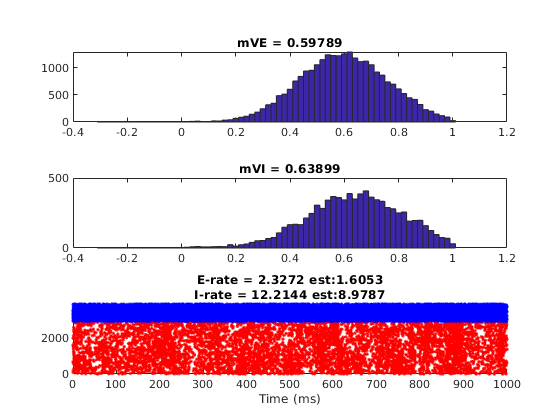

Elapsed time is 28.349151 seconds.
Elapsed time is 31.276456 seconds.
Elapsed time is 34.281725 seconds.
Elapsed time is 37.317159 seconds.
Elapsed time is 40.369377 seconds.
Elapsed time is 43.582833 seconds.
Elapsed time is 46.709081 seconds.
Elapsed time is 49.882778 seconds.
Elapsed time is 53.190267 seconds.
Elapsed time is 56.551288 seconds.


S_EE = 0.024, S_EI = 0.0384, S_IE = 0.01836, S_II = 0.12
S_Elgn = 0.048, lambda_E = 0.08, S_Ilgn = 0.096, lambda_I = 0.08
S_amb = 0.01, rE_amb = 0.5, rI_amb = 0.5

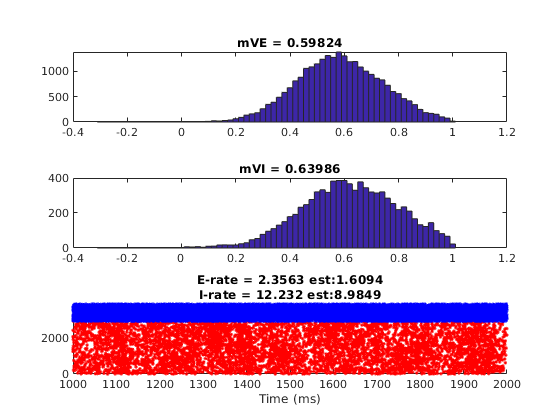

Elapsed time is 60.100920 seconds.
Elapsed time is 63.450756 seconds.
Elapsed time is 66.837954 seconds.


%% Network Simulation
T = 2000; SimulationT = 1000; dt = 0.1;
% E-to-E delay time
T_EEDly = 0.5; N_EEDly = floor(T_EEDly/dt);
T_IEDly = 0.5; N_IEDly = floor(T_IEDly/dt);
% Setup Results Recording
Fr_NW_BG      = zeros(2,1);
mV_NW_BG      = zeros(2,1);
%Fr_OneStep = zeros(2,EITestN,length(S_IEtest)); % one step MF estimation using network mV

% Compute Neuron Ind
% E_sideInd = floor(1*n_E_HC+1):2*n_E_HC;
% [E_Ind_X,E_Ind_Y] = meshgrid(E_sideInd,E_sideInd);
% E_Ind = (reshape(E_Ind_X,size(E_Ind_X,1)*size(E_Ind_X,2),1)-1)*n_E_HC*N_HC + reshape(E_Ind_Y,size(E_Ind_X,1)*size(E_Ind_X,2),1);
% 
% I_sideInd = floor(1*n_I_HC+1):2*n_I_HC;
% [I_Ind_X,I_Ind_Y] = meshgrid(I_sideInd,I_sideInd);
% I_Ind = (reshape(I_Ind_X,size(I_Ind_X,1)*size(I_Ind_X,2),1)-1)*n_I_HC*N_HC + reshape(I_Ind_Y,size(I_Ind_X,1)*size(I_Ind_X,2),1);
% 
% N_EE = mean(sum(C_EE(E_Ind,:),2)); N_EI = mean(sum(C_EI(E_Ind,:),2));
% N_IE = mean(sum(C_IE(I_Ind,:),2)); N_II = mean(sum(C_II(I_Ind,:),2));

% Create sliding windows
sampleT = 200;
Sliding = 100;
NSlide = floor(sampleT/Sliding);
TWinBounds = 0:Sliding:T;
Wins = [];
Wins(:,1) = TWinBounds(1:end-NSlide);
Wins(:,2) = TWinBounds(NSlide+1:end);

% The initial states
InSs = load('Initials_L6.mat');
RefTimeE = InSs.RefTimeE; VE = InSs.VE; SpE = InSs.SpE; GE_ampa_R = InSs.GE_ampa_R; GE_nmda_R = InSs.GE_nmda_R; GE_gaba_R = InSs.GE_gaba_R;
GE_ampa_D = InSs.GE_ampa_D; GE_nmda_D = InSs.GE_nmda_D; GE_gaba_D = InSs.GE_gaba_D;
RefTimeI = InSs.RefTimeI; VI = InSs.VI; SpI = InSs.SpI; GI_ampa_R = InSs.GI_ampa_R; GI_nmda_R = InSs.GI_nmda_R; GI_gaba_R = InSs.GI_gaba_R;
GI_ampa_D = InSs.GI_ampa_D; GI_nmda_D = InSs.GI_nmda_D; GI_gaba_D = InSs.GI_gaba_D;
EEDlyRcd = sparse(N_E,N_EEDly);
IEDlyRcd = sparse(N_I,N_IEDly);
%E_SpHis= []; I_SpHis=[];
E_Sp = []; I_Sp = [];
VE_T = []; VI_T = [];
sampleN = floor(Sliding/dt); % sample each 2 ms
SimulationN = floor(SimulationT/dt); % show and check every 200ms

BlowUp = false;
SampleInd = 1;

% Trace 1. Fr; 2. mV; 3. V distb
NWTrace = struct('FrEs',   zeros(size(Wins(:,1))), 'FrIs',   zeros(size(Wins(:,1))),...
    'mVEs',   zeros(size(Wins(:,1))), 'mVIs',   zeros(size(Wins(:,1))));
NWTrace.VEDist =  cell(size(Wins(:,1)));
NWTrace.VIDist =  cell(size(Wins(:,1)));
NWTrace.Wins = Wins;

tic
for TimeN = 1:floor(T/dt)
    [oRefTimeE,oVE,oSpE,oGE_ampa_R,oGE_nmda_R,oGE_gaba_R,... % Output
        oGE_ampa_D,oGE_nmda_D,oGE_gaba_D,...
        oRefTimeI,oVI,oSpI,oGI_ampa_R,oGI_nmda_R,oGI_gaba_R,...
        oGI_ampa_D,oGI_nmda_D,oGI_gaba_D,...
        oEEDlyRcd,oIEDlyRcd] = ... % A updated N*T Mat recoding the time of kicks taking effect
        V1NetworkUpdate_Ver2_EEnIEDelay(RefTimeE,VE,SpE,GE_ampa_R,GE_nmda_R,GE_gaba_R,... % These are input kept updating
        GE_ampa_D,GE_nmda_D,GE_gaba_D,...
        RefTimeI,VI,SpI,GI_ampa_R,GI_nmda_R,GI_gaba_R,...
        GI_ampa_D,GI_nmda_D,GI_gaba_D,...
        EEDlyRcd,IEDlyRcd,... % A N*T Mat recoding the time of kicks taking effect
        C_EE_Fix_Bd,C_EI_Fix_Bd,C_IE_Fix_Bd,C_II_Fix_Bd,...
        S_EE,S_EI,S_IE,S_II,...
        tau_ampa_R,tau_ampa_D,tau_nmda_R,tau_nmda_D,tau_gaba_R,tau_gaba_D,tau_ref,... % time unit is ms
        dt,p_EEFail,...
        gL_E,Ve,S_Elgn,rhoE_ampa,rhoE_nmda,...
        gL_I,Vi,S_Ilgn,rhoI_ampa,rhoI_nmda,...
        S_amb,lambda_E,lambda_I,rE_amb,rI_amb,...
        S_EL6,S_IL6,rE_L6,rI_L6); % L6 Parameters          % The lower/upper bounds for kick waiting time
    % iteration
    RefTimeE = oRefTimeE; VE = oVE;SpE = oSpE;GE_ampa_R = oGE_ampa_R; GE_nmda_R = oGE_nmda_R; GE_gaba_R = oGE_gaba_R;
    GE_ampa_D = oGE_ampa_D; GE_nmda_D = oGE_nmda_D; GE_gaba_D = oGE_gaba_D;
    RefTimeI = oRefTimeI; VI = oVI;SpI = oSpI;GI_ampa_R = oGI_ampa_R; GI_nmda_R = oGI_nmda_R; GI_gaba_R = oGI_gaba_R;
    GI_ampa_D = oGI_ampa_D; GI_nmda_D = oGI_nmda_D; GI_gaba_D = oGI_gaba_D;
    EEDlyRcd = oEEDlyRcd; IEDlyRcd = oIEDlyRcd;
    
    % When reaching every 500ms, demostrate and pause
    if mod(TimeN,SimulationN) == 0 && TimeN*dt>=400
        ParameterDisp = ['S_EE = ' num2str(S_EE) ', S_EI = ' num2str(S_EI) ...
            ', S_IE = ' num2str(S_IE) ', S_II = ' num2str(S_II) '\n' ...
            'S_Elgn = ' num2str(S_Elgn) ', lambda_E = ' num2str(lambda_E) ...
            ', S_Ilgn = ' num2str(S_Ilgn) ', lambda_I = ' num2str(lambda_I) '\n' ...
            'S_amb = ' num2str(S_amb) ', rE_amb = ' num2str(rE_amb) ', rI_amb = ' num2str(rI_amb)];
        
        fprintf(ParameterDisp)
        figure('Name','TestRaster');
        subplot 311
        hist(oVE,-0.3:0.02:1)
        title(['mVE = ' num2str(nanmean(VE_T))])
        %E_SpHis = [E_SpHis,sum(oSpE)];
        %axis([-0.4 1.1 0 6000])
        
        subplot 312
        hist(oVI,-0.3:0.02:1)
        title(['mVI = ' num2str(nanmean(VI_T))])
              
        %E_Ind = 10000:13000; I_Ind = 3300:4300;
        scatterE = find(ismember(E_Sp(:,1),E_Ind));
        scatterI = find(ismember(I_Sp(:,1),I_Ind));
        [~,E_Fire_Ind] = ismember(E_Sp(scatterE,1),E_Ind);
        [~,I_Fire_Ind] = ismember(I_Sp(scatterI,1),I_Ind);
        
        WinSize = SimulationT;
        T_RateWindow = [TimeN*dt-WinSize TimeN*dt];
        E_SpInd = find(E_Sp(:,2)>=T_RateWindow(1) & E_Sp(:,2)<=T_RateWindow(2) & ismember(E_Sp(:,1),E_Ind));
        I_SpInd = find(I_Sp(:,2)>=T_RateWindow(1) & I_Sp(:,2)<=T_RateWindow(2) & ismember(I_Sp(:,1),I_Ind));
        E_Rate = length(E_SpInd)/(WinSize/1000)/length(E_Ind);
        I_Rate = length(I_SpInd)/(WinSize/1000)/length(I_Ind);
        
        f_EnIOneStep = MeanFieldEst_BkGd_L6_OneStep(N_EE,N_EI,N_IE,N_II,...
                                                    S_EE,S_EI,S_IE,S_II,p_EEFail,...
                                                    lambda_E,S_Elgn,rE_amb,S_amb,...
                                                    lambda_I,S_Ilgn,rI_amb,...
                                                    S_EL6,S_IL6,rE_L6,rI_L6,...
                                                    gL_E,gL_I,Ve,Vi,nanmean(VE_T),nanmean(VI_T));
        %
        subplot 313
        hold on
        scatter(E_Sp(scatterE,2),E_Fire_Ind,'r.')
        scatter(I_Sp(scatterI,2),I_Fire_Ind+max(E_Fire_Ind),'b.');
        title({['E-rate = ' num2str(E_Rate) ' est:' num2str(f_EnIOneStep(1))],['I-rate = ' num2str(I_Rate) ' est:' num2str(f_EnIOneStep(2))]})
        xlabel('Time (ms)')
        xlim(T_RateWindow)
        ylim([0 max(I_Fire_Ind)+max(E_Fire_Ind)])
        drawnow
        %pause
        %close(h)
        % end of 500ms plot
    end
    
    % every 20ms time window
    if mod(TimeN,sampleN) == 0 && TimeN >= floor(sampleT/dt)
        WinSize = NWTrace.Wins(SampleInd,2) - NWTrace.Wins(SampleInd,1);
        T_RateWindow = NWTrace.Wins(SampleInd,:);
        E_SpInd = find(E_Sp(:,2)>=T_RateWindow(1) & E_Sp(:,2)<=T_RateWindow(2) & ismember(E_Sp(:,1),E_Ind));
        I_SpInd = find(I_Sp(:,2)>=T_RateWindow(1) & I_Sp(:,2)<=T_RateWindow(2) & ismember(I_Sp(:,1),I_Ind));
        
        NWTrace.FrEs(SampleInd) = length(E_SpInd)/(WinSize/1000)/length(E_Ind);
        NWTrace.FrIs(SampleInd) = length(I_SpInd)/(WinSize/1000)/length(I_Ind);
        NWTrace.mVEs(SampleInd) = nanmean(oVE(E_Ind));
        NWTrace.mVIs(SampleInd) = nanmean(oVI(I_Ind));
        
        NWTrace.VEDist{SampleInd} = oVE(E_Ind);
        NWTrace.VIDist{SampleInd} = oVI(I_Ind);
        
        SampleInd = SampleInd + 1;
        toc
    end
    
    E_Sp = [E_Sp;[find(oSpE),ones(size(find(oSpE)))*TimeN*dt]];
    I_Sp = [I_Sp;[find(oSpI),ones(size(find(oSpI)))*TimeN*dt]];
    VE_T = [VE_T;nanmean(oVE(E_Ind))];
    VI_T = [VI_T;nanmean(oVI(I_Ind))];
    
    if sum(isnan(oVE))>0.80*N_E
        BlowUp = true;
        disp('warning!: Network exploded')
        break
    end
    
    % the end of iteration
end

toc

NWTrace.E_Sp = E_Sp; NWTrace.I_Sp = I_Sp;


% If blown up, discard other recordings...
if ~BlowUp
    Fr_NW_BG     = [E_Rate;I_Rate];
    mV_NW_BG     = [nanmean(VE_T),nanmean(VI_T)];
    %Fr_OneStep(:,S_EIInd,S_IEInd) = f_EnIOneStep;
end
% end of S_IE loop

## Now, with drive

First figure out orientation domains

ODNum = 4; % 4 orientation domains
% A function from Neuron Ind and spatial scales to Orientation Domains
OD_E = zeros(size(NnE.X),'single');
OD_EMap = zeros(n_E_HC*N_HC,'single');
for NeuInd = 1:length(NnE.X)
OD_E(NeuInd) = OrientDom(ODNum,NnE.X(NeuInd),NnE.Y(NeuInd),n_E_HC);
OD_EMap(NnE.Y(NeuInd),NnE.X(NeuInd)) = OD_E(NeuInd);
end

OD_I = zeros(size(NnI.X),'single');
OD_IMap = zeros(n_I_HC*N_HC,'single');
for NeuInd = 1:length(NnI.X)
OD_I(NeuInd) = OrientDom(ODNum,NnI.X(NeuInd),NnI.Y(NeuInd),n_I_HC);
OD_IMap(NnI.Y(NeuInd),NnI.X(NeuInd)) = OD_I(NeuInd);
end

### Incorporate Phase:

Use an updating vector for each E cell to reflect its on-off phase

Directly pull lgnEevents and do multiplication with the phase factor

StimulusFac = 1;
LGNFreq = 2; % 2Hz
tMod = 1e3/LGNFreq; MaxOnPhase = tMod/2;% Each Cycle lasts for 500 ms
PhaseE = single(tMod*rand(N_E,1));
PhaseFRS = [90 67.5 45 67.5,    0  22.5 45 22.5] *4/1e3 * StimulusFac;
PhaseFRC = [90 67.5 45 67.5,    0  22.5 45 22.5] *1.0/1e3 * StimulusFac;
lambda_EOn_drive  = PhaseFRS(OD_E)'; % Should do another for Cplx cells
lambda_EOff_drive = PhaseFRS(OD_E+ODNum)';
% T partition
T = 10000; dt = 0.1; TPar = 10;

LGN & L6 input classified by domains

Inputs are high now!!! Bernouli may underestimate, and we need to use:

- first simulate Poisson processes

- Feed them to the new function

%DriveE = [60,53,48,53]*4/1e3; % Ordered by domains, times the number of lgn cells, normalized by 1000ms
lambda_E_drive = 45 *4/1e3 * StimulusFac;
lambda_I_drive = 45 *4/1e3 * StimulusFac;

L6E_Drive = [50 35 20 35]*50/1e3 * StimulusFac;
rE_L6_Drive = L6E_Drive(OD_E)';
rI_L6_Drive = 3*L6E_Drive(OD_I)';


% Making Poisson here/Reading
TimeFrac = 0.05;
LGNCurInp = 0;

lgnE_Events = PoissonInputForNetwork(N_E,lambda_E_drive*(1-LGNCurInp),T*TimeFrac,dt);
lgnI_Events = PoissonInputForNetwork(N_I,lambda_I_drive*(1-LGNCurInp),T*TimeFrac,dt);
AmbE_Events = PoissonInputForNetwork(N_E,rE_amb,T*TimeFrac,dt);
AmbI_Events = PoissonInputForNetwork(N_I,rI_amb,T*TimeFrac,dt);

% L6 is much more specific!!! We will make a sum of Poisson and constant
L6CurInp = 0;
L6E_Events  = PoissonInputForNetwork(N_E,rE_L6_Drive*(1-L6CurInp),T*TimeFrac,dt);
L6I_Events  = PoissonInputForNetwork(N_I,rI_L6_Drive*(1-L6CurInp),T*TimeFrac,dt);


Simulation of Drive

Then make a transfer between neurons in HCs and 10*10 pixels

%% Network Simulation
% SimulationT = 5000; 
% E-to-E delay time
T_EEDly = .9; N_EEDly = floor(T_EEDly/dt);
T_IEDly = .5; N_IEDly = floor(T_IEDly/dt);
T_EIDly = .5; N_EIDly = floor(T_EIDly/dt);
% % The initial states
% InSs = load('Initials_L6.mat');
% RefTimeE = InSs.RefTimeE; VE = InSs.VE; SpE = InSs.SpE; GE_ampa_R = InSs.GE_ampa_R; GE_nmda_R = InSs.GE_nmda_R; GE_gaba_R = InSs.GE_gaba_R;
% GE_ampa_D = InSs.GE_ampa_D; GE_nmda_D = InSs.GE_nmda_D; GE_gaba_D = InSs.GE_gaba_D;
% RefTimeI = InSs.RefTimeI; VI = InSs.VI; SpI = InSs.SpI; GI_ampa_R = InSs.GI_ampa_R; GI_nmda_R = InSs.GI_nmda_R; GI_gaba_R = InSs.GI_gaba_R;
% GI_ampa_D = InSs.GI_ampa_D; GI_nmda_D = InSs.GI_nmda_D; GI_gaba_D = InSs.GI_gaba_D;
% EEDlyRcd = sparse(N_E,N_EEDly);

% The initial states, for more simulation 
load(['LargeNWFixIni.mat'],'EndState');
%load('IniTest.mat');
RefTimeE = EndState{1}; VE = EndState{2}; SpE = EndState{3}; GE_ampa_R = EndState{4}; GE_nmda_R = EndState{5}; GE_gaba_R = EndState{6};
                                                             GE_ampa_D = EndState{7}; GE_nmda_D = EndState{8}; GE_gaba_D = EndState{9};
RefTimeI = EndState{10}; VI = EndState{11}; SpI = EndState{12}; GI_ampa_R = EndState{13}; GI_nmda_R = EndState{14}; GI_gaba_R = EndState{15};
                                                                GI_ampa_D = EndState{16}; GI_nmda_D = EndState{17}; GI_gaba_D = EndState{18};
if N_EEDly>=size(EndState{19},2)
EEDlyRcd = [EndState{19},zeros(N_E,N_EEDly-size(EndState{19},2))]; 
else
    EEDlyRcd = EndState{19}(:,1:N_EEDly);
end
if N_IEDly>=size(EndState{20},2)
IEDlyRcd = [EndState{20},zeros(N_I,N_IEDly-size(EndState{20},2))]; 
else
    IEDlyRcd = EndState{20}(:,1:N_IEDly);
end
EIDlyRcd = ones(N_E,N_EIDly);
% Create sliding windows
sampleT = 50;
Sliding = 50;
NSlide = floor(sampleT/Sliding);
TWinBounds = 0:Sliding:T;
Wins = [];
Wins(:,1) = TWinBounds(1:end-NSlide);
Wins(:,2) = TWinBounds(NSlide+1:end);
WinNum = length(Wins);
sampleN = floor(Sliding/dt); % sample each 2 ms
% SimulationN = floor(SimulationT/dt); % show and check every 200ms

BlowUp = false;
SampleInd = 1;

% Trace 1. Fr; 2. mV; 3. V distb
NWTrace = struct('SpEs',   cell(WinNum,1), 'SpIs',   cell(WinNum,1),...
                 'mVEs',   cell(WinNum,1), 'mVIs',   cell(WinNum,1),...
                 'GE_E',   cell(WinNum,1), 'GE_I',   cell(WinNum,1),...
                 'GI_E',   cell(WinNum,1), 'GI_I',   cell(WinNum,1));
%NWTrace.Wins = {Wins};

MaxInpBin = floor(T*TimeFrac/dt);

The biggest problem here is the access to the input matrices

So I do the following:

For every 100ms (1000 bins), first pre-compute input matrices for all (E ampa, Enmda, Iampa, Inmda), then feed into iteration algorithm

Bug here: Though I defined AdjlgnE for every step, it is used only every 100ms...

So: 250on/250off are mixed here...

for TSec = 1:TPar
tic
for TimeN = 1:floor(T/dt/TPar)
    % Zero: Use Phase vec to determine different lgn phases for E neurons
    PhaseE = mod(PhaseE + dt,tMod);      
    % First, Get input matrices from series
    InpWin = 100; FrameNum = floor(InpWin/dt);
    FrameInd = mod(TimeN, FrameNum);
    if FrameInd == 0
    FrameInd = FrameNum;
    end
    RandTimBin = randi([1 MaxInpBin+1],6,FrameNum);
    if FrameInd  == 1 % if the first frame, recompute input mats
        tt = 0:dt:InpWin-dt;
        AdjlgnE = PhaseFRS(floor(mod(PhaseE + tt, tMod)/MaxOnPhase)*ODNum + OD_E');
        AdjlgnE(EcplxInd,:) = PhaseFRC(floor(mod(PhaseE(EcplxInd) + tt, tMod)/MaxOnPhase)*ODNum + OD_E(EcplxInd)');
        EampaInp = single(full(S_Elgn * (lgnE_Events(:,RandTimBin(1,:)) .*AdjlgnE/lambda_E_drive + AdjlgnE*dt*LGNCurInp)...
                             + S_amb  * AmbE_Events(:,RandTimBin(3,:)) ...
                             + S_EL6  * ( L6E_Events(:,RandTimBin(5,:)) + rE_L6_Drive*dt*L6CurInp) * rhoE_ampa)); %  * rhoE_ampa
        IampaInp = single(full(S_Ilgn * (lgnI_Events(:,RandTimBin(2,:)) + lambda_I_drive*dt*LGNCurInp) ...
                             + S_amb  * AmbI_Events(:,RandTimBin(4,:)) ...
                             + S_IL6  * ( L6I_Events(:,RandTimBin(6,:)) + rI_L6_Drive*dt*L6CurInp) * rhoI_ampa)); %  * rhoI_ampa
        
        EnmdaInp = single(full(S_EL6  * ( L6E_Events(:,RandTimBin(5,:)) + rE_L6_Drive*dt*L6CurInp) * rhoE_nmda)); % 
        InmdaInp = single(full(S_IL6  * ( L6I_Events(:,RandTimBin(6,:)) + rI_L6_Drive*dt*L6CurInp) * rhoI_nmda));
        
    end
    
   
%      lgnEVec = zeros(N_E,1);lgnIVec = zeros(N_I,1);
%      AmbEVec = zeros(N_E,1);AmbIVec = zeros(N_I,1);
%      L6EVec = zeros(N_E,1); L6IVec = zeros(N_I,1);
   [oRefTimeE,oVE,oSpE,oGE_ampa_R,oGE_nmda_R,oGE_gaba_R,... % Output
                             oGE_ampa_D,oGE_nmda_D,oGE_gaba_D,...
          oRefTimeI,oVI,oSpI,oGI_ampa_R,oGI_nmda_R,oGI_gaba_R,...
                             oGI_ampa_D,oGI_nmda_D,oGI_gaba_D,...
                             oEEDlyRcd,oIEDlyRcd, oEIDlyRcd] = ... % A updated N*T Mat recoding the time of kicks taking effect
   V1NetworkUpdate_Ver3_Drive_PoissonRead_EEnIEnEIDelay(RefTimeE,VE,SpE,GE_ampa_R,GE_nmda_R,GE_gaba_R,... % These are input kept updating
                                                        GE_ampa_D,GE_nmda_D,GE_gaba_D,...
                                                        RefTimeI,VI,SpI,GI_ampa_R,GI_nmda_R,GI_gaba_R,...
                                                        GI_ampa_D,GI_nmda_D,GI_gaba_D,...
                                                        EEDlyRcd,IEDlyRcd, EIDlyRcd,... % A N*T Mat recoding the time of kicks taking effect
                          C_EE_Fix_Bd,C_EI_Fix_Bd,C_IE_Fix_Bd,C_II_Fix_Bd,...
                          S_EE,S_EI,S_IE,S_II,...
                          tau_ampa_R,tau_ampa_D,tau_nmda_R,tau_nmda_D,tau_gaba_R,tau_gaba_D,tau_ref,... % time unit is ms
                          dt,p_EEFail,...
                          gL_E,Ve,rhoE_ampa,rhoE_nmda,...
                          gL_I,Vi,rhoI_ampa,rhoI_nmda,...
                          EampaInp(:,FrameInd), IampaInp(:,FrameInd),...
                          EnmdaInp(:,FrameInd), InmdaInp(:,FrameInd));
    % iteration
    RefTimeE = oRefTimeE; VE = oVE;SpE = oSpE;GE_ampa_R = oGE_ampa_R; GE_nmda_R = oGE_nmda_R; GE_gaba_R = oGE_gaba_R;
    GE_ampa_D = oGE_ampa_D; GE_nmda_D = oGE_nmda_D; GE_gaba_D = oGE_gaba_D;
    RefTimeI = oRefTimeI; VI = oVI;SpI = oSpI;GI_ampa_R = oGI_ampa_R; GI_nmda_R = oGI_nmda_R; GI_gaba_R = oGI_gaba_R;
    GI_ampa_D = oGI_ampa_D; GI_nmda_D = oGI_nmda_D; GI_gaba_D = oGI_gaba_D;
    EEDlyRcd = oEEDlyRcd; IEDlyRcd = oIEDlyRcd; EIDlyRcd = oEIDlyRcd;

    % Record Every Time time window
    RecordNum = floor(sampleT/dt);
    RecordInd = mod(TimeN, RecordNum);
    SampleRate = 0.1; % Can't be too small for multiple phases
    if RecordInd == 1
        clear E_Sp I_Sp mVETemp mVITemp
        E_Sp = [];
        I_Sp = [];
        mVETemp = zeros(N_E,floor(RecordNum*SampleRate),'single');
        mVITemp = zeros(N_I,floor(RecordNum*SampleRate),'single');
        GE_ETemp = zeros(N_E,floor(RecordNum*SampleRate),'single');
        GE_ITemp = zeros(N_E,floor(RecordNum*SampleRate),'single');
        GI_ETemp = zeros(N_I,floor(RecordNum*SampleRate),'single');
        GI_ITemp = zeros(N_I,floor(RecordNum*SampleRate),'single');
        mVRecordInd = 1;        
    elseif RecordInd == 0 
        NWTrace(SampleInd).mVEs = mVETemp;
        NWTrace(SampleInd).mVIs = mVITemp;
        
        NWTrace(SampleInd).SpEs = E_Sp;
        NWTrace(SampleInd).SpIs = I_Sp;
        
        NWTrace(SampleInd).GE_I = GE_ITemp;
        NWTrace(SampleInd).GE_E = GE_ETemp;
        NWTrace(SampleInd).GI_I = GI_ITemp;
        NWTrace(SampleInd).GI_E = GI_ETemp;
        SampleInd = SampleInd + 1
        %sum(isnan(oVE))/N_E
        FrESNow = sum(ismember(E_Sp(:,1), find(~EcplxInd)))/N_S/sampleT*1000
        FrECNow = sum(ismember(E_Sp(:,1), find(EcplxInd)))/N_C/sampleT*1000
        FrINow = size(I_Sp,1)/N_I/sampleT*1000
        toc        
    end
    E_Sp = single([E_Sp;[find(oSpE),ones(size(find(oSpE)))*TimeN*dt]]);
    I_Sp = single([I_Sp;[find(oSpI),ones(size(find(oSpI)))*TimeN*dt]]);
    
    if mod(TimeN,floor(1/SampleRate)) == 5
        mVETemp(:,mVRecordInd) = oVE;
        mVITemp(:,mVRecordInd) = oVI;
        % Precompute GE GI
        GE_I = 1/(tau_gaba_D-tau_gaba_R) * (GE_gaba_D - GE_gaba_R); % S_EI is included in amplitude of GE_gaba
        GE_E = 1/(tau_ampa_D-tau_ampa_R) * (GE_ampa_D - GE_ampa_R) + ...
               1/(tau_nmda_D-tau_nmda_R) * (GE_nmda_D - GE_nmda_R); %                       

        GI_I = 1/(tau_gaba_D-tau_gaba_R) * (GI_gaba_D - GI_gaba_R); % S_EI is included in amplitude of GE_gaba
        GI_E = 1/(tau_ampa_D-tau_ampa_R) * (GI_ampa_D - GI_ampa_R) + ...
               1/(tau_nmda_D-tau_nmda_R) * (GI_nmda_D - GI_nmda_R); %                       
        GE_ITemp(:,mVRecordInd) = GE_I;
        GE_ETemp(:,mVRecordInd) = GE_E;
        GI_ITemp(:,mVRecordInd) = GI_I;
        GI_ETemp(:,mVRecordInd) = GI_E;
        %record loop goes forward
        mVRecordInd = mVRecordInd + 1; 
    end
    
%     if sum(isnan(oVE))>0.80*N_E
%         BlowUp = true;
%         disp('warning!: Network exploded')
%         break
%     end
    
    % the end of iteration
end
toc
text = ['DriveWkSp_Cplx' num2str(TSec) 's.mat'];
EndState = {RefTimeE, VE, SpE, GE_ampa_R, GE_nmda_R, GE_gaba_R, GE_ampa_D, GE_nmda_D, GE_gaba_D,...
            RefTimeI, VI, SpI, GI_ampa_R, GI_nmda_R, GI_gaba_R, GI_ampa_D, GI_nmda_D, GI_gaba_D,...
            EEDlyRcd, IEDlyRcd};
save([SaveFolder text],'NWTrace','EndState','PhaseE','-v7.3')

clear NWTrace
NWTrace = struct('SpEs',   cell(WinNum,1), 'SpIs',   cell(WinNum,1),...
                 'mVEs',   cell(WinNum,1), 'mVIs',   cell(WinNum,1),...
                 'GE_E',   cell(WinNum,1), 'GE_I',   cell(WinNum,1),...
                 'GI_E',   cell(WinNum,1), 'GI_I',   cell(WinNum,1));
end
save([SaveFolder,'DriveWkSp_Cplx_Conn.mat'],'CMatAll','EcplxInd');

SampleInd = 2

FrESNow = 12.0973

FrECNow = 17.7014

FrINow = 57.8587

Elapsed time is 2.438943 seconds.


SampleInd = 3

FrESNow = 10.7351

FrECNow = 14.3776

FrINow = 55.0561

Elapsed time is 3.987469 seconds.


SampleInd = 4

FrESNow = 11.7243

FrECNow = 19.6668

FrINow = 61.1331

Elapsed time is 6.334047 seconds.


SampleInd = 5

FrESNow = 11.8789

FrECNow = 20.1601

FrINow = 62.2592

Elapsed time is 8.009189 seconds.


SampleInd = 6

FrESNow = 11.4627

FrECNow = 18.4323

FrINow = 60.5064

Elapsed time is 10.265136 seconds.


SampleInd = 7

FrESNow = 12.4422

FrECNow = 23.1560

FrINow = 65.6608

Elapsed time is 12.008300 seconds.


SampleInd = 8

FrESNow = 10.5265

FrECNow = 14.3208

FrINow = 56.5938

Elapsed time is 14.114926 seconds.


SampleInd = 9

FrESNow = 11.3957

FrECNow = 17.8926

FrINow = 59.6346

Elapsed time is 15.579425 seconds.


SampleInd = 10

FrESNow = 12.0681

FrECNow = 25.5320

FrINow = 67.4783

Elapsed time is 17.940673 seconds.


SampleInd = 11

FrESNow = 10.0076

FrECNow = 12.7970

FrINow = 54.1057

Elapsed time is 19.286664 seconds.


SampleInd = 12

FrESNow = 11.4573

FrECNow = 19.8037

FrINow = 60.9689

Elapsed time is 21.497208 seconds.


SampleInd = 13

FrESNow = 11.4595

FrECNow = 19.7211

FrINow = 61.5539

Elapsed time is 23.020144 seconds.


SampleInd = 14

FrESNow = 11.5265

FrECNow = 19.7314

FrINow = 61.5008

Elapsed time is 25.217286 seconds.


SampleInd = 15

FrESNow = 11.4205

FrECNow = 18.0372

FrINow = 60.5920

Elapsed time is 26.752446 seconds.


SampleInd = 16

FrESNow = 12.0584

FrECNow = 21.1596

FrINow = 63.7299

Elapsed time is 29.073940 seconds.


SampleInd = 17

FrESNow = 11.1654

FrECNow = 16.7407

FrINow = 59.0612

Elapsed time is 30.697552 seconds.


SampleInd = 18

FrESNow = 11.6984

FrECNow = 21.5625

FrINow = 63.7692

Elapsed time is 32.955463 seconds.


SampleInd = 19

FrESNow = 11.1351

FrECNow = 17.1668

FrINow = 59.4612

Elapsed time is 34.479919 seconds.


SampleInd = 20

FrESNow = 11.4011

FrECNow = 18.3574

FrINow = 60.4070

Elapsed time is 36.757084 seconds.


SampleInd = 21

FrESNow = 11.4519

FrECNow = 21.3662

FrINow = 63.3761

Elapsed time is 38.423251 seconds.


Elapsed time is 38.424036 seconds.


SampleInd = 22

FrESNow = 10.6627

FrECNow = 15.8781

FrINow = 57.1534

Elapsed time is 2.236773 seconds.


SampleInd = 23

FrESNow = 11.4454

FrECNow = 19.6746

FrINow = 61.3181

Elapsed time is 3.864540 seconds.


SampleInd = 24

FrESNow = 10.8368

FrECNow = 16.6374

FrINow = 58.2033

Elapsed time is 6.120032 seconds.


SampleInd = 25

FrESNow = 12.4097

FrECNow = 23.6338

FrINow = 65.8666

Elapsed time is 7.763511 seconds.


SampleInd = 26

FrESNow = 10.5730

FrECNow = 14.2794

FrINow = 56.1568

Elapsed time is 9.946058 seconds.


SampleInd = 27

FrESNow = 12.2962

FrECNow = 22.4845

FrINow = 64.7682

Elapsed time is 11.587140 seconds.


SampleInd = 28

FrESNow = 10.9492

FrECNow = 17.3528

FrINow = 59.0519

Elapsed time is 13.751453 seconds.


SampleInd = 29

FrESNow = 11.3405

FrECNow = 19.2665

FrINow = 61.4545

Elapsed time is 15.386171 seconds.


SampleInd = 30

FrESNow = 11.5568

FrECNow = 20.6818

FrINow = 62.8697

Elapsed time is 17.667956 seconds.


SampleInd = 31

FrESNow = 10.6151

FrECNow = 15.4545

FrINow = 56.7395

Elapsed time is 19.141905 seconds.


SampleInd = 32

FrESNow = 11.4324

FrECNow = 24.2330

FrINow = 65.0757

Elapsed time is 21.539137 seconds.


SampleInd = 33

FrESNow = 10.3676

FrECNow = 13.4504

FrINow = 54.8156

Elapsed time is 23.017719 seconds.


SampleInd = 34

FrESNow = 12.6022

FrECNow = 25.5010

FrINow = 67.5338

Elapsed time is 25.407019 seconds.


SampleInd = 35

FrESNow = 10.4843

FrECNow = 14.9380

FrINow = 56.9060

Elapsed time is 26.900099 seconds.


SampleInd = 36

FrESNow = 11.2443

FrECNow = 18.6260

FrINow = 60.2428

Elapsed time is 29.174454 seconds.


SampleInd = 37

FrESNow = 11.8281

FrECNow = 20.2454

FrINow = 62.2847

Elapsed time is 30.788123 seconds.


SampleInd = 38

FrESNow = 11.0519

FrECNow = 17.1513

FrINow = 58.9733

Elapsed time is 32.937338 seconds.


SampleInd = 39

FrESNow = 11.7070

FrECNow = 20.9840

FrINow = 62.9668

Elapsed time is 34.552658 seconds.


SampleInd = 40

FrESNow = 11.3200

FrECNow = 17.7583

FrINow = 60.0879

Elapsed time is 36.796401 seconds.


SampleInd = 41

FrESNow = 11.7968

FrECNow = 19.8528

FrINow = 62.2638

Elapsed time is 38.414356 seconds.


Elapsed time is 38.415067 seconds.


SampleInd = 42

FrESNow = 10.5827

FrECNow = 17.7660

FrINow = 58.8900

Elapsed time is 2.241721 seconds.


SampleInd = 43

FrESNow = 11.4930

FrECNow = 20.4442

FrINow = 61.9840

Elapsed time is 3.837428 seconds.


SampleInd = 44

FrESNow = 10.8757

FrECNow = 17.2082

FrINow = 58.7490

Elapsed time is 5.968176 seconds.


SampleInd = 45

FrESNow = 11.8216

FrECNow = 20.2531

FrINow = 62.1020

Elapsed time is 7.615581 seconds.


SampleInd = 46

FrESNow = 11.3114

FrECNow = 19.9535

FrINow = 61.4984

Elapsed time is 9.813102 seconds.


SampleInd = 47

FrESNow = 11.2941

FrECNow = 15.8574

FrINow = 58.4553

Elapsed time is 11.312014 seconds.


SampleInd = 48

FrESNow = 11.5092

FrECNow = 19.6410

FrINow = 61.3204

Elapsed time is 13.568000 seconds.


SampleInd = 49

FrESNow = 11.3708

FrECNow = 18.5124

FrINow = 60.2867

Elapsed time is 15.201153 seconds.


SampleInd = 50

FrESNow = 11.5503

FrECNow = 20.0542

FrINow = 62.1390

Elapsed time is 17.460158 seconds.


SampleInd = 51

FrESNow = 10.9232

FrECNow = 16.9447

FrINow = 58.9178

Elapsed time is 18.938324 seconds.


SampleInd = 52

FrESNow = 11.3308

FrECNow = 19.4602

FrINow = 60.8602

Elapsed time is 21.204697 seconds.


SampleInd = 53

FrESNow = 11.3232

FrECNow = 19.3156

FrINow = 61.2788

Elapsed time is 22.712175 seconds.


SampleInd = 54

FrESNow = 10.5254

FrECNow = 14.6952

FrINow = 55.8053

Elapsed time is 24.774122 seconds.


SampleInd = 55

FrESNow = 11.9135

FrECNow = 20.3693

FrINow = 62.4604

Elapsed time is 26.418882 seconds.


SampleInd = 56

FrESNow = 10.9481

FrECNow = 16.0124

FrINow = 57.5142

Elapsed time is 28.602766 seconds.


SampleInd = 57

FrESNow = 12.2951

FrECNow = 21.8750

FrINow = 64.2941

Elapsed time is 30.187663 seconds.


SampleInd = 58

FrESNow = 10.7232

FrECNow = 16.8027

FrINow = 58.3605

Elapsed time is 32.296443 seconds.


SampleInd = 59

FrESNow = 12.6454

FrECNow = 26.1777

FrINow = 68.5605

Elapsed time is 33.993549 seconds.


SampleInd = 60

FrESNow = 10.4227

FrECNow = 15.3874

FrINow = 57.6460

Elapsed time is 36.197136 seconds.


SampleInd = 61

FrESNow = 11.5070

FrECNow = 19.9664

FrINow = 61.9309

Elapsed time is 37.847760 seconds.


Elapsed time is 37.848470 seconds.


SampleInd = 62

FrESNow = 11.3178

FrECNow = 19.7443

FrINow = 61.5146

Elapsed time is 2.323108 seconds.


SampleInd = 63

FrESNow = 10.5492

FrECNow = 15.8704

FrINow = 56.9337

Elapsed time is 3.885948 seconds.


SampleInd = 64

FrESNow = 11.9903

FrECNow = 21.4773

FrINow = 63.6952

Elapsed time is 6.098212 seconds.


SampleInd = 65

FrESNow = 11.1773

FrECNow = 18.3626

FrINow = 60.3422

Elapsed time is 7.680462 seconds.


SampleInd = 66

FrESNow = 11.1135

FrECNow = 17.1074

FrINow = 59.1698

Elapsed time is 9.858511 seconds.


SampleInd = 67

FrESNow = 11.6465

FrECNow = 19.3337

FrINow = 61.4268

Elapsed time is 11.477987 seconds.


SampleInd = 68

FrESNow = 11.2703

FrECNow = 18.3342

FrINow = 60.3445

Elapsed time is 13.614702 seconds.


SampleInd = 69

FrESNow = 11.5168

FrECNow = 18.6829

FrINow = 60.7631

Elapsed time is 15.212267 seconds.


SampleInd = 70

FrESNow = 11.5114

FrECNow = 20.8858

FrINow = 62.9298

Elapsed time is 17.411957 seconds.


SampleInd = 71

FrESNow = 10.9384

FrECNow = 16.3507

FrINow = 57.6737

Elapsed time is 18.910098 seconds.


SampleInd = 72

FrESNow = 11.6908

FrECNow = 20.8910

FrINow = 62.6986

Elapsed time is 21.138302 seconds.


SampleInd = 73

FrESNow = 10.8865

FrECNow = 16.7355

FrINow = 58.4044

Elapsed time is 22.609952 seconds.


SampleInd = 74

FrESNow = 11.9081

FrECNow = 22.2314

FrINow = 64.0143

Elapsed time is 24.913458 seconds.


SampleInd = 75

FrESNow = 10.8649

FrECNow = 16.9706

FrINow = 58.7490

Elapsed time is 26.484334 seconds.


SampleInd = 76

FrESNow = 12.2195

FrECNow = 22.7454

FrINow = 64.7589

Elapsed time is 28.763326 seconds.


SampleInd = 77

FrESNow = 10.6897

FrECNow = 15.1498

FrINow = 57.1072

Elapsed time is 30.296827 seconds.


SampleInd = 78

FrESNow = 11.4346

FrECNow = 19.2846

FrINow = 61.2903

Elapsed time is 32.488258 seconds.


SampleInd = 79

FrESNow = 11.0054

FrECNow = 15.9607

FrINow = 57.5396

Elapsed time is 33.959340 seconds.


SampleInd = 80

FrESNow = 12.2281

FrECNow = 25.0181

FrINow = 67.4367

Elapsed time is 36.293063 seconds.


SampleInd = 81

FrESNow = 10.2411

FrECNow = 12.3993

FrINow = 53.9484

Elapsed time is 37.759088 seconds.


Elapsed time is 37.759789 seconds.


SampleInd = 82

FrESNow = 11.7092

FrECNow = 22.0661

FrINow = 63.6767

Elapsed time is 2.333283 seconds.


SampleInd = 83

FrESNow = 10.8562

FrECNow = 15.3796

FrINow = 56.8505

Elapsed time is 3.784696 seconds.


SampleInd = 84

FrESNow = 11.3276

FrECNow = 20.4442

FrINow = 61.6765

Elapsed time is 6.011650 seconds.


SampleInd = 85

FrESNow = 11.3751

FrECNow = 17.5491

FrINow = 59.8011

Elapsed time is 7.648891 seconds.


SampleInd = 86

FrESNow = 11.3178

FrECNow = 18.2490

FrINow = 59.9191

Elapsed time is 9.912170 seconds.


SampleInd = 87

FrESNow = 12.2141

FrECNow = 25.1033

FrINow = 67.1268

Elapsed time is 11.597942 seconds.


SampleInd = 88

FrESNow = 10.1027

FrECNow = 13.5124

FrINow = 54.9913

Elapsed time is 13.683138 seconds.


SampleInd = 89

FrESNow = 11.8984

FrECNow = 20.5811

FrINow = 62.6523

Elapsed time is 15.335952 seconds.


SampleInd = 90

FrESNow = 12.2865

FrECNow = 22.4329

FrINow = 65.6677

Elapsed time is 17.621520 seconds.


SampleInd = 91

FrESNow = 10.4303

FrECNow = 15.1007

FrINow = 57.0031

Elapsed time is 19.049058 seconds.


SampleInd = 92

FrESNow = 11.1027

FrECNow = 17.6188

FrINow = 58.8600

Elapsed time is 21.202288 seconds.


SampleInd = 93

FrESNow = 11.3762

FrECNow = 20.0568

FrINow = 61.7967

Elapsed time is 22.757969 seconds.


SampleInd = 94

FrESNow = 11.1351

FrECNow = 16.6761

FrINow = 58.4877

Elapsed time is 24.954840 seconds.


SampleInd = 95

FrESNow = 11.8627

FrECNow = 19.9122

FrINow = 62.0858

Elapsed time is 26.533906 seconds.


SampleInd = 96

FrESNow = 11.3265

FrECNow = 18.5821

FrINow = 60.3376

Elapsed time is 28.835469 seconds.


SampleInd = 97

FrESNow = 11.7081

FrECNow = 19.6668

FrINow = 62.0604

Elapsed time is 30.507401 seconds.


SampleInd = 98

FrESNow = 11.0054

FrECNow = 17.0635

FrINow = 59.1999

Elapsed time is 32.745681 seconds.


SampleInd = 99

FrESNow = 11.6324

FrECNow = 19.9406

FrINow = 61.9100

Elapsed time is 34.398115 seconds.


SampleInd = 100

FrESNow = 11.5557

FrECNow = 20.0103

FrINow = 62.3078

Elapsed time is 36.703712 seconds.


SampleInd = 101

FrESNow = 10.6714

FrECNow = 15.2583

FrINow = 56.9060

Elapsed time is 38.177135 seconds.


Elapsed time is 38.177924 seconds.


SampleInd = 102

FrESNow = 11.9989

FrECNow = 24.3595

FrINow = 66.0099

Elapsed time is 2.428339 seconds.


SampleInd = 103

FrESNow = 10.5946

FrECNow = 15.6457

FrINow = 57.2159

Elapsed time is 3.958187 seconds.


SampleInd = 104

FrESNow = 11.8735

FrECNow = 21.3352

FrINow = 63.0871

Elapsed time is 6.262502 seconds.


SampleInd = 105

FrESNow = 10.9016

FrECNow = 14.9148

FrINow = 57.0702

Elapsed time is 7.789092 seconds.


SampleInd = 106

FrESNow = 12.3881

FrECNow = 22.8512

FrINow = 65.1428

Elapsed time is 10.166739 seconds.


SampleInd = 107

FrESNow = 10.8595

FrECNow = 16.7924

FrINow = 58.7236

Elapsed time is 11.744110 seconds.


SampleInd = 108

FrESNow = 11.4281

FrECNow = 18.5589

FrINow = 60.5943

Elapsed time is 13.989326 seconds.


SampleInd = 109

FrESNow = 11.8638

FrECNow = 23.3110

FrINow = 65.3185

Elapsed time is 15.600319 seconds.


SampleInd = 110

FrESNow = 10.6011

FrECNow = 14.0780

FrINow = 55.9094

Elapsed time is 17.757520 seconds.


SampleInd = 111

FrESNow = 11.2205

FrECNow = 20.8394

FrINow = 62.2453

Elapsed time is 19.405367 seconds.


SampleInd = 112

FrESNow = 11.3784

FrECNow = 19.8631

FrINow = 61.1169

Elapsed time is 21.633324 seconds.


SampleInd = 113

FrESNow = 10.9135

FrECNow = 17.7815

FrINow = 59.1629

Elapsed time is 23.132239 seconds.


SampleInd = 114

FrESNow = 11.1546

FrECNow = 17.9881

FrINow = 59.3109

Elapsed time is 25.415978 seconds.


SampleInd = 115

FrESNow = 11.9070

FrECNow = 20.1188

FrINow = 62.0557

Elapsed time is 27.082919 seconds.


SampleInd = 116

FrESNow = 11.4422

FrECNow = 19.3259

FrINow = 61.8291

Elapsed time is 29.396699 seconds.


SampleInd = 117

FrESNow = 11.4151

FrECNow = 18.1379

FrINow = 60.2012

Elapsed time is 30.932643 seconds.


SampleInd = 118

FrESNow = 11.2227

FrECNow = 19.0677

FrINow = 60.7145

Elapsed time is 33.239629 seconds.


SampleInd = 119

FrESNow = 11.2054

FrECNow = 18.0759

FrINow = 59.6948

Elapsed time is 34.782417 seconds.


SampleInd = 120

FrESNow = 11.8486

FrECNow = 22.7970

FrINow = 64.8167

Elapsed time is 37.067815 seconds.


SampleInd = 121

FrESNow = 10.7146

FrECNow = 15.4959

FrINow = 57.4934

Elapsed time is 38.604999 seconds.


Elapsed time is 38.605677 seconds.


SampleInd = 122

FrESNow = 11.2195

FrECNow = 18.1043

FrINow = 60.0046

Elapsed time is 2.261322 seconds.


SampleInd = 123

FrESNow = 11.3459

FrECNow = 18.2051

FrINow = 59.7595

Elapsed time is 3.776100 seconds.


SampleInd = 124

FrESNow = 11.2422

FrECNow = 17.8693

FrINow = 59.5306

Elapsed time is 6.017761 seconds.


SampleInd = 125

FrESNow = 11.7157

FrECNow = 21.4282

FrINow = 63.5380

Elapsed time is 7.656536 seconds.


SampleInd = 126

FrESNow = 11.0789

FrECNow = 16.2577

FrINow = 58.1408

Elapsed time is 9.791984 seconds.


SampleInd = 127

FrESNow = 11.9114

FrECNow = 21.1467

FrINow = 63.4524

Elapsed time is 11.393756 seconds.


SampleInd = 128

FrESNow = 10.8476

FrECNow = 16.6426

FrINow = 58.4784

Elapsed time is 13.549454 seconds.


SampleInd = 129

FrESNow = 10.9827

FrECNow = 17.2443

FrINow = 58.6380

Elapsed time is 15.167074 seconds.


SampleInd = 130

FrESNow = 11.5892

FrECNow = 20.4985

FrINow = 62.9136

Elapsed time is 17.531098 seconds.


SampleInd = 131

FrESNow = 11.0919

FrECNow = 18.1741

FrINow = 59.8266

Elapsed time is 19.075415 seconds.


SampleInd = 132

FrESNow = 10.8303

FrECNow = 15.9633

FrINow = 57.2066

Elapsed time is 21.208879 seconds.


SampleInd = 133

FrESNow = 11.5784

FrECNow = 19.5713

FrINow = 60.8648

Elapsed time is 22.856253 seconds.


SampleInd = 134

FrESNow = 12.1611

FrECNow = 22.1952

FrINow = 64.5462

Elapsed time is 25.185523 seconds.


SampleInd = 135

FrESNow = 10.6227

FrECNow = 14.3750

FrINow = 56.0250

Elapsed time is 26.662039 seconds.


SampleInd = 136

FrESNow = 11.9135

FrECNow = 22.4974

FrINow = 64.5231

Elapsed time is 28.965503 seconds.


SampleInd = 137

FrESNow = 10.8832

FrECNow = 16.3017

FrINow = 58.0021

Elapsed time is 30.491543 seconds.


SampleInd = 138

FrESNow = 11.2692

FrECNow = 18.6415

FrINow = 60.2983

Elapsed time is 32.779379 seconds.


SampleInd = 139

FrESNow = 11.5438

FrECNow = 19.2949

FrINow = 61.2741

Elapsed time is 34.446083 seconds.


SampleInd = 140

FrESNow = 10.8195

FrECNow = 17.2753

FrINow = 58.5825

Elapsed time is 36.563717 seconds.


SampleInd = 141

FrESNow = 11.3870

FrECNow = 20.8445

FrINow = 62.7726

Elapsed time is 38.257531 seconds.


Elapsed time is 38.258195 seconds.


SampleInd = 142

FrESNow = 11.0227

FrECNow = 16.6271

FrINow = 58.2287

Elapsed time is 2.274082 seconds.


SampleInd = 143

FrESNow = 11.7157

FrECNow = 20.9168

FrINow = 62.4535

Elapsed time is 3.983509 seconds.


SampleInd = 144

FrESNow = 10.9438

FrECNow = 17.3270

FrINow = 59.0126

Elapsed time is 6.148266 seconds.


SampleInd = 145

FrESNow = 11.7459

FrECNow = 21.3972

FrINow = 63.5750

Elapsed time is 7.787485 seconds.


SampleInd = 146

FrESNow = 10.7892

FrECNow = 16.4437

FrINow = 57.7038

Elapsed time is 10.025651 seconds.


SampleInd = 147

FrESNow = 11.7622

FrECNow = 19.9277

FrINow = 61.9979

Elapsed time is 11.623905 seconds.


SampleInd = 148

FrESNow = 11.4508

FrECNow = 19.3079

FrINow = 61.3551

Elapsed time is 13.815341 seconds.


SampleInd = 149

FrESNow = 11.1924

FrECNow = 17.3244

FrINow = 59.4358

Elapsed time is 15.372958 seconds.


SampleInd = 150

FrESNow = 11.4681

FrECNow = 19.6978

FrINow = 61.7806

Elapsed time is 17.631660 seconds.


SampleInd = 151

FrESNow = 10.1049

FrECNow = 14.5894

FrINow = 55.0445

Elapsed time is 19.062033 seconds.


SampleInd = 152

FrESNow = 11.3762

FrECNow = 19.7753

FrINow = 60.7353

Elapsed time is 21.319666 seconds.


SampleInd = 153

FrESNow = 11.5276

FrECNow = 19.8528

FrINow = 61.6719

Elapsed time is 22.910420 seconds.


SampleInd = 154

FrESNow = 11.2151

FrECNow = 17.5336

FrINow = 59.6670

Elapsed time is 25.193423 seconds.


SampleInd = 155

FrESNow = 11.9319

FrECNow = 22.7583

FrINow = 65.0387

Elapsed time is 26.872655 seconds.


SampleInd = 156

FrESNow = 10.5481

FrECNow = 14.4551

FrINow = 56.0689

Elapsed time is 28.953736 seconds.


SampleInd = 157

FrESNow = 12.0454

FrECNow = 22.9468

FrINow = 65.0272

Elapsed time is 30.677766 seconds.


SampleInd = 158

FrESNow = 10.8227

FrECNow = 15.5527

FrINow = 57.1118

Elapsed time is 32.836659 seconds.


SampleInd = 159

FrESNow = 11.5816

FrECNow = 20.3022

FrINow = 62.3957

Elapsed time is 34.501826 seconds.


SampleInd = 160

FrESNow = 11.4389

FrECNow = 18.4168

FrINow = 60.7053

Elapsed time is 36.808167 seconds.


SampleInd = 161

FrESNow = 10.9730

FrECNow = 17.5646

FrINow = 59.1513

Elapsed time is 38.287751 seconds.


Elapsed time is 38.288476 seconds.


SampleInd = 162

FrESNow = 11.1070

FrECNow = 17.8719

FrINow = 59.4681

Elapsed time is 2.148119 seconds.


SampleInd = 163

FrESNow = 11.3741

FrECNow = 20.4675

FrINow = 61.7852

Elapsed time is 3.822637 seconds.


SampleInd = 164

FrESNow = 10.9362

FrECNow = 16.4437

FrINow = 58.0160

Elapsed time is 6.006568 seconds.


SampleInd = 165

FrESNow = 11.2724

FrECNow = 19.6720

FrINow = 60.9319

Elapsed time is 7.621206 seconds.


SampleInd = 166

FrESNow = 11.8962

FrECNow = 19.7340

FrINow = 61.8268

Elapsed time is 9.936924 seconds.


SampleInd = 167

FrESNow = 10.9741

FrECNow = 17.3244

FrINow = 59.6323

Elapsed time is 11.540376 seconds.


SampleInd = 168

FrESNow = 12.1135

FrECNow = 20.6767

FrINow = 62.7957

Elapsed time is 13.790485 seconds.


SampleInd = 169

FrESNow = 11.1135

FrECNow = 16.3559

FrINow = 58.1871

Elapsed time is 15.348828 seconds.


SampleInd = 170

FrESNow = 11.2130

FrECNow = 21.4669

FrINow = 62.8396

Elapsed time is 17.656039 seconds.


SampleInd = 171

FrESNow = 11.6086

FrECNow = 20.7231

FrINow = 62.8350

Elapsed time is 19.259967 seconds.


SampleInd = 172

FrESNow = 9.9341

FrECNow = 14.8115

FrINow = 55.6527

Elapsed time is 21.348202 seconds.


SampleInd = 173

FrESNow = 12.0984

FrECNow = 24.0444

FrINow = 65.4064

Elapsed time is 23.041263 seconds.


SampleInd = 174

FrESNow = 10.9005

FrECNow = 16.4489

FrINow = 58.2541

Elapsed time is 25.124470 seconds.


SampleInd = 175

FrESNow = 11.2411

FrECNow = 18.1457

FrINow = 59.7017

Elapsed time is 26.629749 seconds.


SampleInd = 176

FrESNow = 11.4335

FrECNow = 19.6823

FrINow = 61.2649

Elapsed time is 28.830500 seconds.


SampleInd = 177

FrESNow = 11.6519

FrECNow = 20.0826

FrINow = 62.5205

Elapsed time is 30.359961 seconds.


SampleInd = 178

FrESNow = 11.6422

FrECNow = 20.7180

FrINow = 63.1634

Elapsed time is 32.558107 seconds.


SampleInd = 179

FrESNow = 10.5935

FrECNow = 14.3053

FrINow = 56.0296

Elapsed time is 33.952419 seconds.


SampleInd = 180

FrESNow = 11.8757

FrECNow = 21.6322

FrINow = 63.8964

Elapsed time is 36.190698 seconds.


SampleInd = 181

FrESNow = 10.4476

FrECNow = 16.0434

FrINow = 56.9291

Elapsed time is 37.721489 seconds.


Elapsed time is 37.722470 seconds.


SampleInd = 182

FrESNow = 11.6216

FrECNow = 19.2717

FrINow = 60.9596

Elapsed time is 2.343516 seconds.


SampleInd = 183

FrESNow = 11.1568

FrECNow = 16.9137

FrINow = 58.7143

Elapsed time is 3.951429 seconds.


SampleInd = 184

FrESNow = 11.4843

FrECNow = 21.4592

FrINow = 62.8419

Elapsed time is 6.207181 seconds.


SampleInd = 185

FrESNow = 10.9384

FrECNow = 17.5129

FrINow = 59.1860

Elapsed time is 7.760547 seconds.


SampleInd = 186

FrESNow = 11.7114

FrECNow = 19.7288

FrINow = 61.8014

Elapsed time is 10.058469 seconds.


SampleInd = 187

FrESNow = 11.2941

FrECNow = 17.5181

FrINow = 59.4728

Elapsed time is 11.587805 seconds.


SampleInd = 188

FrESNow = 11.6681

FrECNow = 19.9303

FrINow = 62.3540

Elapsed time is 13.924452 seconds.


SampleInd = 189

FrESNow = 11.1319

FrECNow = 17.1204

FrINow = 59.2508

Elapsed time is 15.461210 seconds.


SampleInd = 190

FrESNow = 11.3676

FrECNow = 19.2485

FrINow = 60.7608

Elapsed time is 17.697832 seconds.


SampleInd = 191

FrESNow = 11.3827

FrECNow = 20.5914

FrINow = 62.4465

Elapsed time is 19.362565 seconds.


SampleInd = 192

FrESNow = 10.4216

FrECNow = 14.9974

FrINow = 56.3325

Elapsed time is 21.570765 seconds.


SampleInd = 193

FrESNow = 12.1297

FrECNow = 23.5666

FrINow = 65.1104

Elapsed time is 23.285600 seconds.


SampleInd = 194

FrESNow = 10.6724

FrECNow = 17.0041

FrINow = 58.1801

Elapsed time is 25.434289 seconds.


SampleInd = 195

FrESNow = 10.8703

FrECNow = 16.0847

FrINow = 57.3800

Elapsed time is 26.912327 seconds.


SampleInd = 196

FrESNow = 12.4249

FrECNow = 22.2443

FrINow = 65.0064

Elapsed time is 29.266737 seconds.


SampleInd = 197

FrESNow = 10.9330

FrECNow = 17.8977

FrINow = 59.5722

Elapsed time is 30.809576 seconds.


SampleInd = 198

FrESNow = 11.2400

FrECNow = 16.9473

FrINow = 59.1421

Elapsed time is 33.090153 seconds.


SampleInd = 199

FrESNow = 12.0011

FrECNow = 20.6043

FrINow = 62.9807

Elapsed time is 34.716204 seconds.


SampleInd = 200

FrESNow = 10.6638

FrECNow = 15.7774

FrINow = 57.4355

Elapsed time is 36.792828 seconds.


SampleInd = 201

FrESNow = 11.4530

FrECNow = 19.8399

FrINow = 61.3620

Elapsed time is 38.301452 seconds.


Elapsed time is 38.302103 seconds.


### Plot Spatial maps: load data

% read data, and get spike and mV
SpE = []; SpI = [];
mVE = []; mVI = []; % These are the total data
GE_E = []; GE_I = [];
GI_E = []; GI_I = [];
PhaseEAll = [];
for TSec = 1:TPar
    text = ['DriveWkSp_Cplx' num2str(TSec) 's.mat'];
    load([SaveFolder text],'NWTrace');
    
    SpECurrent = []; SpICurrent = [];
    mVECurrent = []; mVICurrent = [];
    GE_ECurrent = [];GE_ICurrent = [];
    GI_ECurrent = [];GI_ICurrent = [];
    PhaseECurrent = [];
    for WinInd = 1:length(NWTrace)
    SpECurrent = [SpECurrent; NWTrace(WinInd).SpEs];
    SpICurrent = [SpICurrent; NWTrace(WinInd).SpIs];
    mVECurrent = [mVECurrent, NWTrace(WinInd).mVEs];
    mVICurrent = [mVICurrent, NWTrace(WinInd).mVIs];
    
%     GE_ECurrent = [GE_ECurrent, NWTrace(WinInd).GE_E];
%     GE_ICurrent = [GE_ICurrent, NWTrace(WinInd).GE_I];
%     GI_ECurrent = [GI_ECurrent, NWTrace(WinInd).GI_E];
%     GI_ICurrent = [GI_ICurrent, NWTrace(WinInd).GI_I];
    end
    SpECurrent(:,2) = SpECurrent(:,2) + (TSec-1)*T/TPar;
    SpICurrent(:,2) = SpICurrent(:,2) + (TSec-1)*T/TPar;
    SpE = [SpE;SpECurrent];
    SpI = [SpI;SpICurrent];
    mVE = [mVE,mVECurrent];
    mVI = [mVI,mVICurrent];
    
%     GE_E = [GE_E, GE_ECurrent]; 
%     GE_I = [GE_I, GE_ICurrent];
%     GI_E = [GI_E, GI_ECurrent]; 
%     GI_I = [GI_I, GI_ICurrent];
    
end
load([SaveFolder text],'PhaseE');
load([SaveFolder 'DriveWkSp_Cplx_Conn.mat'],'CMatAll','EcplxInd');

C_EE_Fix_Bd = CMatAll.C_EE_Fix_Bd ;
C_EI_Fix_Bd = CMatAll.C_EI_Fix_Bd ;
C_IE_Fix_Bd = CMatAll.C_IE_Fix_Bd ;
C_II_Fix_Bd = CMatAll.C_II_Fix_Bd ;

WinNum = size(mVE,2);
StatWin = linspace(0,T,WinNum+1);
StatWinSize = StatWin(2) - StatWin(1);

Check soome time dependency// cental hypercolum??

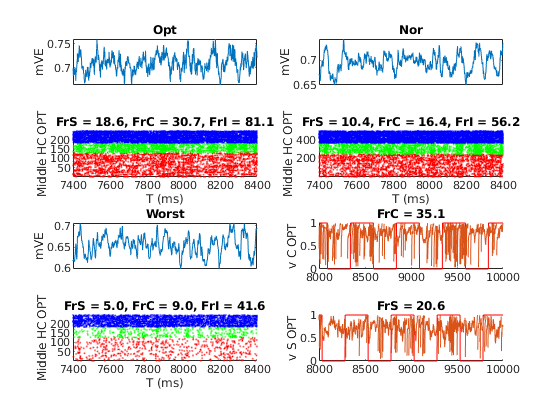

OptE = OD_E==1;           OptI = OD_I==1;
WorstE = OD_E==3;         WorstI = OD_I==3;
NorE = OD_E==2 | OD_E==4; NorI = OD_I==2 | OD_I==4;

MidColE = NnE.X>=1.25*n_E_HC & NnE.X<=1.75*n_E_HC;
MidRowE = NnE.Y>=1.25*n_E_HC & NnE.Y<=1.75*n_E_HC;
MidHCE = MidColE & MidRowE;

MidColI = NnI.X>=1.25*n_I_HC & NnI.X<=1.75*n_I_HC;
MidRowI = NnI.Y>=1.25*n_I_HC & NnI.Y<=1.75*n_I_HC;
MidHCI= MidColI & MidRowI;

ShowWin = [7400 8400];
SOpt = find(OptE & ~EcplxInd);
scatterSOpt = find(ismember(SpE(:,1), SOpt));
[~,SOpt_Ind] = ismember(SpE(scatterSOpt,1),scatterSOpt);
FrSOpt = length(SpE(scatterSOpt,2))/(T/1e3)/length(SOpt);

COpt = find(OptE & EcplxInd);
scatterCOpt = find(ismember(SpE(:,1), COpt));
[~,COpt_Ind] = ismember(SpE(scatterCOpt,1),scatterCOpt);
FrCOpt = length(SpE(scatterCOpt,2))/(T/1e3)/length(COpt);

figure('Name','Domain Range')
OD1E = find(OptE & MidHCE);
OD1S = find(OptE & MidHCE & (~EcplxInd));
OD1C = find(OptE & MidHCE & (EcplxInd));
OD1I = find(OptI & MidHCI);
scatter1S = find(ismember(SpE(:,1),OD1S));
scatter1C = find(ismember(SpE(:,1),OD1C));
scatter1I = find(ismember(SpI(:,1),OD1I));
[~,OD1S_Ind] = ismember(SpE(scatter1S,1),OD1S);
[~,OD1C_Ind] = ismember(SpE(scatter1C,1),OD1C);
[~,OD1I_Ind] = ismember(SpI(scatter1I,1),OD1I);
subplot 423
hold on
scatter(SpE(scatter1S,2),OD1S_Ind,0.5,'r.')
scatter(SpE(scatter1C,2),OD1C_Ind+max(OD1S_Ind),0.5,'g.')
scatter(SpI(scatter1I,2),OD1I_Ind+length(OD1E),0.5,'b.');  
FrS1 = length(SpE(scatter1S,2))/(T/1e3)/length(OD1S);
FrC1 = length(SpE(scatter1C,2))/(T/1e3)/length(OD1C);
FrI1 = length(SpI(scatter1I,2))/(T/1e3)/length(OD1I);
title(sprintf('FrS = %.1f, FrC = %.1f, FrI = %.1f',FrS1,FrC1,FrI1))
xlabel('T (ms)'); ylabel('Middle HC OPT')
axis tight
xlim(ShowWin)
subplot 421
plot(StatWin(1:WinNum),nanmean(mVE(OD1E,:)))
ylabel('mVE')
set(gca,'xtick','')
title('Opt')
xlim(ShowWin)

OD2E = find(NorE & MidHCE);
OD2S = find(NorE & MidHCE & (~EcplxInd));
OD2C = find(NorE & MidHCE & (EcplxInd));
OD2I = find(NorI & MidHCI);
scatter2S = find(ismember(SpE(:,1),OD2S));
scatter2C = find(ismember(SpE(:,1),OD2C));
scatter2I = find(ismember(SpI(:,1),OD2I));
[~,OD2S_Ind] = ismember(SpE(scatter2S,1),OD2S);
[~,OD2C_Ind] = ismember(SpE(scatter2C,1),OD2C);
[~,OD2I_Ind] = ismember(SpI(scatter2I,1),OD2I);
subplot 424
hold on
scatter(SpE(scatter2S,2),OD2S_Ind,0.5,'r.')
scatter(SpE(scatter2C,2),OD2C_Ind+max(OD2S_Ind),0.5,'g.')
scatter(SpI(scatter2I,2),OD2I_Ind+length(OD2E),0.5,'b.');  
FrS2 = length(SpE(scatter2S,2))/(T/1e3)/length(OD2S);
FrC2 = length(SpE(scatter2C,2))/(T/1e3)/length(OD2C);
FrI2 = length(SpI(scatter2I,2))/(T/1e3)/length(OD2I);
title(sprintf('FrS = %.1f, FrC = %.1f, FrI = %.1f',FrS2,FrC2,FrI2))
xlabel('T (ms)'); ylabel('Middle HC OPT')
axis tight
xlim(ShowWin)
subplot 422
plot(StatWin(1:WinNum),nanmean(mVE(OD2E,:)))
ylabel('mVE')
set(gca,'xtick','')
title('Nor')
xlim(ShowWin)

OD3E = find(WorstE & MidHCE);
OD3S = find(WorstE & MidHCE & (~EcplxInd));
OD3C = find(WorstE & MidHCE & (EcplxInd));
OD3I = find(WorstI & MidHCI);
scatter3S = find(ismember(SpE(:,1),OD3S));
scatter3C = find(ismember(SpE(:,1),OD3C));
scatter3I = find(ismember(SpI(:,1),OD3I));
[~,OD3S_Ind] = ismember(SpE(scatter3S,1),OD3S);
[~,OD3C_Ind] = ismember(SpE(scatter3C,1),OD3C);
[~,OD3I_Ind] = ismember(SpI(scatter3I,1),OD3I);
subplot 427
hold on
scatter(SpE(scatter3S,2),OD3S_Ind,0.5,'r.')
scatter(SpE(scatter3C,2),OD3C_Ind+max(OD3S_Ind),0.5,'g.')
scatter(SpI(scatter3I,2),OD3I_Ind+length(OD3E),0.5,'b.');  
FrS3 = length(SpE(scatter3S,2))/(T/1e3)/length(OD3S);
FrC3 = length(SpE(scatter3C,2))/(T/1e3)/length(OD3C);
FrI3 = length(SpI(scatter3I,2))/(T/1e3)/length(OD3I);
title(sprintf('FrS = %.1f, FrC = %.1f, FrI = %.1f',FrS3,FrC3,FrI3))
xlabel('T (ms)'); ylabel('Middle HC OPT')
axis tight
xlim(ShowWin)
subplot 425
plot(StatWin(1:WinNum),nanmean(mVE(OD3E,:)))
ylabel('mVE')
set(gca,'xtick','')
title('Worst')
xlim(ShowWin)

% subplot 427
% hist(SpE(ismember(SpE(:,1),find(NorE & MidHCE)),2),0:1:T)
% xlabel('T (ms)'); ylabel('Spike count for all E cells')
% axis tight
% xlim(ShowWin)
% subplot 425
% plot(StatWin(1:WinNum),nanmean(mVE(OD_E'==2| OD_E'==4,:)))
% ylabel('mVE')
% set(gca,'xtick','')
% xlim(ShowWin)
tCorrect = linspace(-T,0,WinNum+1); % Use mV recording time grid
subplot 426
hold on
NeuInd = OD1C(5);
OnOff = double(~logical(floor(mod(PhaseE(NeuInd,:) + tCorrect,tMod)/MaxOnPhase)));
plot(StatWin,OnOff,'r')
plot(StatWin(1:WinNum),mVE(NeuInd,:))
xlim([8e3 10e3])
Fr1E1 = length(SpE(ismember(SpE(:,1),NeuInd),2))/(T/1e3)/1;
title(sprintf('FrC = %.1f',Fr1E1))
ylabel('v C OPT')
subplot 428
hold on
NeuInd = OD1S(1);
OnOff = double(~logical(floor(mod(PhaseE(NeuInd,:) + tCorrect,tMod)/MaxOnPhase)));
plot(StatWin,OnOff,'r')
plot(StatWin(1:WinNum),mVE(NeuInd,:))
xlim([8e3 10e3])
Fr1E2 = length(SpE(ismember(SpE(:,1),NeuInd),2))/(T/1e3)/1;
title(sprintf('FrS = %.1f',Fr1E2))
ylabel('v S OPT')
% OD_EMapTry = OD_EMap;
% OD_EMapTry([1:54,109:161],:) = 0;
% OD_EMapTry(:,[1:54,109:161]) = 0;

% OptOne = find(OD_EMapTry(:)==1);
% hist(SpE(ismember(SpE(:,1),OptOne),2),0:1:T)

### Plot Spatial maps: Plot

WinSize = 9000;
Window = [T-WinSize T];
EffSize = Window(2)-max(0,Window(1));

tCorrect = linspace(-T,0,WinNum+1); % Use mV recording time grid
OnOffmV = ~logical(floor(mod(...
                             repmat(PhaseE, 1, WinNum) + repmat(tCorrect(1:end-1), N_E, 1), ...
                             tMod)/MaxOnPhase));
OnOffSpE =  ~logical(floor(mod(...
                               PhaseE(SpE(:,1)) - T + SpE(:,2),...
                               tMod)/MaxOnPhase));

% PixelNum per HC
NPixX = 10; %10
NPixY = 10;

NnS.X = NnE.X(~EcplxInd); NnS.Y = NnE.Y(~EcplxInd);
NnC.X = NnE.X(EcplxInd); NnC.Y = NnE.Y(EcplxInd);

FrERan = [3 48];
mVERan = [0.63 0.78];

Figure for ONOFF

First create an onoff vec for each spike

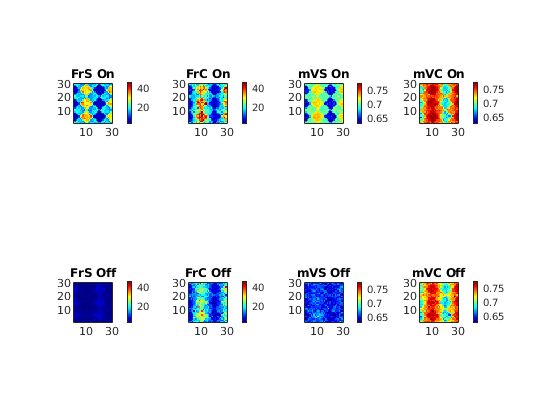

hFrVOnOff = figure('Name','Field_f&V');
% Firing rates:S
subplot 241
ESPinWinOn = SpE(:,2)>=Window(1) & SpE(:,2)<=Window(2) & OnOffSpE;
SpEGoodOn = SpE(ESPinWinOn,1);
[SpCNOn, SpCIOn] = groupcounts(SpEGoodOn);
FrEOn_temp = zeros(N_E,1);
FrEOn_temp(SpCIOn) = SpCNOn*1e3/(EffSize/2);
[FrSOnPixMat,~] = NeuVec2Pixel(FrEOn_temp(~EcplxInd),NnS,NPixX*N_HC,NPixY*N_HC);
imagesc(FrSOnPixMat); title('FrS On')
set(gca,'YDir','normal')
axis square
colormap jet; caxis(FrERan)
colorbar

subplot 245
ESPinWinOff = SpE(:,2)>=Window(1) & SpE(:,2)<=Window(2) & ~OnOffSpE;
SpEGoodOff = SpE(ESPinWinOff,1);
[SpCNOff, SpCIOff] = groupcounts(SpEGoodOff);
FrEOff_temp = zeros(N_E,1);
FrEOff_temp(SpCIOff) = SpCNOff*1e3/(EffSize/2);
[FrSOffPixMat,~] = NeuVec2Pixel(FrEOff_temp(~EcplxInd),NnS,NPixX*N_HC,NPixY*N_HC);
imagesc(FrSOffPixMat); title('FrS Off')
set(gca,'YDir','normal')
axis square
colormap jet ; caxis(FrERan)
colorbar

% Firing rates: C
subplot 242
[FrCOnPixMat,~] = NeuVec2Pixel(FrEOn_temp(EcplxInd),NnC,NPixX*N_HC,NPixY*N_HC);
imagesc(FrCOnPixMat); title('FrC On')
set(gca,'YDir','normal')
axis square
colormap jet; caxis(FrERan)
colorbar

subplot 246
[FrCOffPixMat,~] = NeuVec2Pixel(FrEOff_temp(EcplxInd),NnC,NPixX*N_HC,NPixY*N_HC);
imagesc(FrCOffPixMat); title('FrC Off')
set(gca,'YDir','normal')
axis square
colormap jet ; caxis(FrERan)
colorbar

Win2Col = floor((Window)/(T/size(mVE,2)));
SmallWinRange = Win2Col(1):Win2Col(2);
% mVs: S
OnmVPhase = double(OnOffmV);
OnmVPhase(~OnOffmV) = nan;
mVEOn = mVE; mVEOn = mVEOn.*OnmVPhase;
mVEOn_temp = nanmean(mVEOn(:,SmallWinRange),2);

subplot 243
[mVSOnPixMat,~] = NeuVec2Pixel(mVEOn_temp(~EcplxInd),NnS,NPixX*N_HC,NPixY*N_HC);
imagesc(mVSOnPixMat); title('mVS On')
set(gca,'YDir','normal')
axis square
colormap jet
colorbar; caxis(mVERan)

OffmVPhase = double(~OnOffmV);
OffmVPhase(OnOffmV) = nan;
mVEOff = mVE; mVEOff = mVEOff.*OffmVPhase;
mVEOff_temp = nanmean(mVEOff(:,SmallWinRange),2);

subplot 247
[mVSOffPixMat,~] = NeuVec2Pixel(mVEOff_temp(~EcplxInd),NnS,NPixX*N_HC,NPixY*N_HC);
imagesc(mVSOffPixMat); title('mVS Off')
set(gca,'YDir','normal')
axis square
colormap jet
colorbar; caxis(mVERan)

% mVs: C
subplot 244
[mVCOnPixMat,~] = NeuVec2Pixel(mVEOn_temp(EcplxInd),NnC,NPixX*N_HC,NPixY*N_HC);
imagesc(mVCOnPixMat); title('mVC On')
set(gca,'YDir','normal')
axis square
colormap jet
colorbar; caxis(mVERan)

subplot 248
[mVCOffPixMat,~] = NeuVec2Pixel(mVEOff_temp(EcplxInd),NnC,NPixX*N_HC,NPixY*N_HC);
imagesc(mVCOffPixMat); title('mVC Off')
set(gca,'YDir','normal')
axis square
colormap jet
colorbar; caxis(mVERan)


% % mGs
% subplot 243

% GEEOn = GE_E; GEEOn = GEEOn.*OnmVPhase;
% GEEOn_temp = nanmean(GEEOn(:,SmallWinRange),2);
% [GEEOnPixMat,~] = NeuVec2Pixel(GEEOn_temp,NnE,NPixX*N_HC,NPixY*N_HC);
% imagesc(GEEOnPixMat); title('GEE On')
% set(gca,'YDir','normal')
% axis square
% colormap jet
% colorbar; %caxis([0.66 0.76])
% 
% subplot 247
% GEEOff = GE_E; GEEOff = GEEOff.*OffmVPhase;
% GEEOff_temp = nanmean(GEEOff(:,SmallWinRange),2);
% [GEEOffPixMat,~] = NeuVec2Pixel(GEEOff_temp,NnE,NPixX*N_HC,NPixY*N_HC);
% imagesc(GEEOffPixMat); title('GEE Off')
% set(gca,'YDir','normal')
% axis square
% colormap jet
% colorbar; %caxis([0.66 0.76])
% 
% subplot 244
% GEIOn = GE_I; GEIOn = GEIOn.*OnmVPhase;
% GEIOn_temp = nanmean(GEIOn(:,SmallWinRange),2);
% [GEIOnPixMat,~] = NeuVec2Pixel(GEIOn_temp,NnE,NPixX*N_HC,NPixY*N_HC);
% imagesc(GEIOnPixMat); title('GEI On')
% set(gca,'YDir','normal')
% axis square
% colormap jet
% colorbar; %caxis([0.66 0.76])
% 
% subplot 248
% GEIOff = GE_I; GEIOff = GEIOff.*OffmVPhase;
% GEIOff_temp = nanmean(GEIOff(:,SmallWinRange),2);
% [GEIOffPixMat,~] = NeuVec2Pixel(GEIOff_temp,NnE,NPixX*N_HC,NPixY*N_HC);
% imagesc(GEIOffPixMat); title('GEI Off')
% set(gca,'YDir','normal')
% axis square
% colormap jet
% colorbar; %caxis([0.66 0.76])

Figure for All Average

hFrVAll = figure('Name','Field_f&V');
ESPinWin = SpE(:,2)>=Window(1) & SpE(:,2)<=Window(2);
SpEGood = SpE(ESPinWin,1);
[SpCN, SpCI] = groupcounts(SpEGood);
FrE_temp = zeros(N_E,1);
FrE_temp(SpCI) = SpCN*1e3/(EffSize);
FrE_Map = reshape(FrE_temp,N_HC*n_E_HC,N_HC*n_E_HC); % not used here

subplot 231
[FrSPixMat,NnSPixel] = NeuVec2Pixel(FrE_temp(~EcplxInd),NnS,NPixX*N_HC,NPixY*N_HC);
imagesc(FrSPixMat); title('FrS')
set(gca,'YDir','normal')
axis square
colormap jet
colorbar
subplot 232
[FrCPixMat,NnCPixel] = NeuVec2Pixel(FrE_temp(EcplxInd),NnC,NPixX*N_HC,NPixY*N_HC);
imagesc(FrCPixMat); title('FrC')
set(gca,'YDir','normal')
axis square
colormap jet
colorbar

subplot 234
ISPinWin = (SpI(:,2)>=Window(1) & SpI(:,2)<=Window(2));
SpIGood = SpI(ISPinWin,1);
[SpCN, SpCI] = groupcounts(SpIGood);
FrI_temp = zeros(N_I,1);
FrI_temp(SpCI) = SpCN*1e3/EffSize;
FrI_Map = reshape(FrI_temp,N_HC*n_I_HC,N_HC*n_I_HC);

[FrIPixMat,NnIPixel] = NeuVec2Pixel(FrI_temp,NnI,NPixX*N_HC,NPixY*N_HC);
imagesc(FrIPixMat); title('FrI')
set(gca,'YDir','normal')
axis square
colormap jet
colorbar

Win2Col = floor((Window)/(T/size(mVE,2)));
SmallWinRange = Win2Col(1):Win2Col(2);
subplot 235
mVI_temp = nanmean(mVI(:,SmallWinRange),2);
mVI_Map = reshape(mVI_temp,N_HC*n_I_HC,N_HC*n_I_HC);

[mVIPixMat,~] = NeuVec2Pixel(mVI_temp,NnI,NPixX*N_HC,NPixY*N_HC);
imagesc(mVIPixMat); title('mVI')
set(gca,'YDir','normal')
axis square
colormap jet
colorbar

% Orientation domain
subplot 233
imagesc(OD_EMap);axis square
set(gca,'YDir','normal')

subplot 236
imagesc(OD_IMap);axis square
set(gca,'YDir','normal')

Complex % Simple spikes

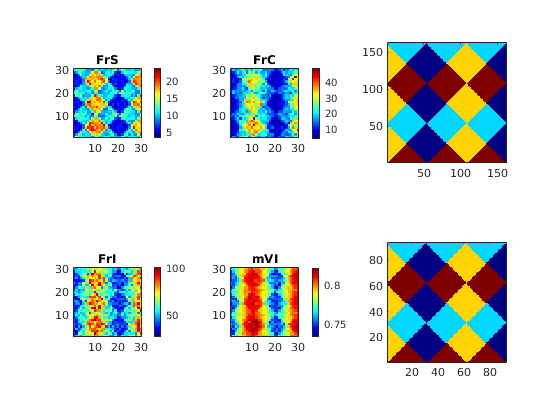

% end of 500ms plot
OPTC = find(OD_E == 1 & EcplxInd);
OPTS = find(OD_E == 1 & ~EcplxInd);

WORST = find(OD_E == 3);
MID = find(OD_E == 2 | OD_E == 4);
hSpCount = figure('Name','SpCountE')
USE = [1,50,300,1000 1500];
for subInd = 1:5
    subplot(6,2,2*subInd-1)
    NeuInd = OPTS(USE(subInd));

hSpCount =   Figure (15: SpCountE) with properties:

      Number: 15
        Name: 'SpCountE'
       Color: [0.9400 0.9400 0.9400]
    Position: [1761 1399 560 420]
       Units: 'pixels'

  Show all properties


    hold on
    hist(SpE(ismember(SpE(:,1),NeuInd),2),0:10:T)
    OnOff = double(~logical(floor(mod(PhaseE(NeuInd) + tCorrect(1:end-1),tMod)/MaxOnPhase)));
    plot(StatWin(1:WinNum),OnOff,'r')
    xlim([0 T])
    xlabel('T (ms)')
    ylabel('Sp Count (per 100ms)')
    if subInd ==1
        title('Simple')
    end
    
    subplot(6,2,2*subInd)
    NeuInd = OPTC(USE(subInd));
    hold on
    hist(SpE(ismember(SpE(:,1),NeuInd),2),0:10:T)
    OnOff = double(~logical(floor(mod(PhaseE(NeuInd) + tCorrect(1:end-1),tMod)/MaxOnPhase)));
    plot(StatWin(1:WinNum),OnOff,'r')
    xlim([0 T])
    xlabel('T (ms)')
    ylabel('Sp Count (per 100ms)')
    
    if subInd ==1
        title('Cplx')
    end
    
end
OPTS = OptE & ~EcplxInd;
OPTC = OptE & EcplxInd;
subplot(6,2,11)   
hist(FrEOn_temp(OPTS))
title(sprintf('FrS OPT = %.1f', mean(FrEOn_temp(OPTS))))
subplot(6,2,12)   
hist(FrEOn_temp(OPTC))
title(sprintf('FrS OPT = %.1f', mean(FrEOn_temp(OPTC))))
%save('DriveWkSp.mat')

## MF linear equation for pixels: 1 Matrices

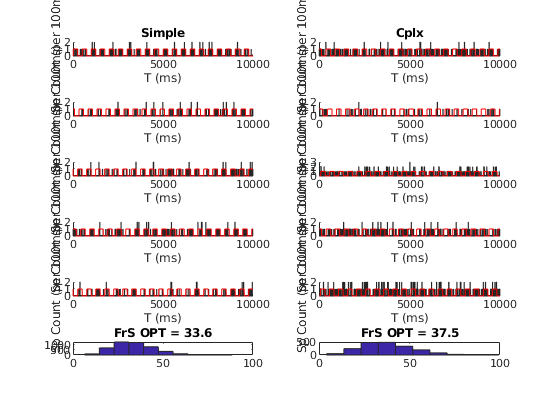

PixNum = NPixX*N_HC * NPixY*N_HC;
% First, get connectivity matrix between Pixels

C_EE_Pixel = zeros(PixNum);
C_EI_Pixel = zeros(PixNum);
C_IE_Pixel = zeros(PixNum);
C_II_Pixel = zeros(PixNum);
% look into std as well
C_EE_Pixelstd = zeros(PixNum);
C_EI_Pixelstd = zeros(PixNum);
C_IE_Pixelstd = zeros(PixNum);
C_II_Pixelstd = zeros(PixNum);
tic
AA = PixNum;
parfor PixIndPost = 1:AA
    for PixIndPre = 1:AA
        C_EE_Pixel(PixIndPost,PixIndPre) = mean(sum(C_EE_Fix_Bd(NnEPixel.Vec == PixIndPost, NnEPixel.Vec == PixIndPre),2));
        C_EI_Pixel(PixIndPost,PixIndPre) = mean(sum(C_EI_Fix_Bd(NnEPixel.Vec == PixIndPost, NnIPixel.Vec == PixIndPre),2));
        C_IE_Pixel(PixIndPost,PixIndPre) = mean(sum(C_IE_Fix_Bd(NnIPixel.Vec == PixIndPost, NnEPixel.Vec == PixIndPre),2));
        C_II_Pixel(PixIndPost,PixIndPre) = mean(sum(C_II_Fix_Bd(NnIPixel.Vec == PixIndPost, NnIPixel.Vec == PixIndPre),2));
        C_EE_Pixelstd(PixIndPost,PixIndPre) = std(sum(C_EE_Fix_Bd(NnEPixel.Vec == PixIndPost, NnEPixel.Vec == PixIndPre),2));
        C_EI_Pixelstd(PixIndPost,PixIndPre) = std(sum(C_EI_Fix_Bd(NnEPixel.Vec == PixIndPost, NnIPixel.Vec == PixIndPre),2));
        C_IE_Pixelstd(PixIndPost,PixIndPre) = std(sum(C_IE_Fix_Bd(NnIPixel.Vec == PixIndPost, NnEPixel.Vec == PixIndPre),2));
        C_II_Pixelstd(PixIndPost,PixIndPre) = std(sum(C_II_Fix_Bd(NnIPixel.Vec == PixIndPost, NnIPixel.Vec == PixIndPre),2));
    end    
end
toc
C_EE_Pixel_Us = sparse(C_EE_Pixel);
C_IE_Pixel_Us = sparse(C_IE_Pixel);
C_EI_Pixel_Us = sparse(C_EI_Pixel);
C_II_Pixel_Us = sparse(C_II_Pixel);
save([SaveFolder 'ConnPixel.mat'], 'C_EE_Pixel_Us','C_IE_Pixel_Us',...
                                   'C_II_Pixel_Us','C_EI_Pixel_Us')
% Present connectivity mats
figure
subplot 221
imagesc(C_EE_Pixel)
colormap jet
colorbar
axis square
title('Mean of connectivities')
subplot 222
imagesc(C_EE_Pixelstd)
axis square
colorbar
title('Std of connectivities')
subplot 223
imagesc(C_EE_Pixelstd./C_EE_Pixel)
axis square
colorbar
title('std/mean')

## Clear redundant variables for memory

clear C_EE C_EE_Fix_Bd C_EI C_EI_Fix_Bd...
      C_IE C_IE_Fix_Bd C_II C_II_Fix_Bd...
      ESPinWin ESPinWinOn ESPinWinOff ISPinWin...
      OffmVPhase OnmVPhase OnOffmV OnOffSpE...
      SpE SpECurrent SpEGood SpEGoodOff SpEGoodOn SpI SpICurrent SpIGood...
      mVE mVEOff mVEOn mVI

MF linear equation for pixels: 2 MF Eqns

load([SaveFolder 'ConnPixel.mat'])
C_EE_Pixel_Us = full(C_EE_Pixel_Us);
C_IE_Pixel_Us = full(C_IE_Pixel_Us);
C_EI_Pixel_Us = full(C_EI_Pixel_Us);
C_II_Pixel_Us = full(C_II_Pixel_Us);

PixNum = NPixX*N_HC * NPixY*N_HC;
FrEPixVec = reshape(FrEPixMat,PixNum,1);
FrEOnPixVec  = reshape(FrEOnPixMat,PixNum,1);
FrEOffPixVec = reshape(FrEOffPixMat,PixNum,1);
FrIPixVec = reshape(FrIPixMat,PixNum,1);

mVEPixVec = reshape(mVEPixMat,PixNum,1);
mVEOnPixVec  = reshape(mVEOnPixMat,PixNum,1);
mVEOffPixVec = reshape(mVEOffPixMat,PixNum,1);
mVIPixVec = reshape(mVIPixMat,PixNum,1);

% Precompute LGN and L6
lambda_EOn_Pixel = zeros(PixNum,1);
lambda_EOff_Pixel = zeros(PixNum,1);
L6E_Pixel = zeros(PixNum,1);
L6I_Pixel = zeros(PixNum,1);
for PixInd = 1:PixNum
    lambda_EOn_Pixel(PixInd)  = mean(lambda_EOn_drive(NnEPixel.Vec == PixInd));
    lambda_EOff_Pixel(PixInd) = mean(lambda_EOff_drive(NnEPixel.Vec == PixInd));
    L6E_Pixel(PixInd) = mean(rE_L6_Drive(NnEPixel.Vec == PixInd));
    L6I_Pixel(PixInd) = mean(rI_L6_Drive(NnIPixel.Vec == PixInd));
end
lambda_I_Pixel = lambda_I_drive;

% Setup preused Firing rates for off E
%FrPreUseDim = find(lambda_EOff_Pixel<0.08) + PixNum;
FrPreUseDim = (1:PixNum) + PixNum;
%FrPreUse = FrEOffPixVec(FrPreUseDim - PixNum); 
FrPreUse = FrEOffLIF(FrPreUseDim - PixNum); 
%FrPreUse = [];


% Mats
MatEE = (S_EE*(1-p_EEFail))*full(C_EE_Pixel_Us); % Need Ref here??
MatEI = S_EI *              full(C_EI_Pixel_Us);
MatIE = S_IE *              full(C_IE_Pixel_Us).*(Ve-repmat(mVIPixVec,1,PixNum));
MatII = S_II *              full(C_II_Pixel_Us).*(Vi-repmat(mVIPixVec,1,PixNum));
ConnMat = [MatEE.*(Ve-repmat(mVEOnPixVec,1,PixNum))/2 , MatEE.*(Ve-repmat(mVEOnPixVec,1,PixNum))/2 , MatEI.*(Vi-repmat(mVEOnPixVec,1,PixNum));
           MatEE.*(Ve-repmat(mVEOffPixVec,1,PixNum))/2, MatEE.*(Ve-repmat(mVEOffPixVec,1,PixNum))/2, MatEI.*(Vi-repmat(mVEOffPixVec,1,PixNum));
           MatIE/2                                    , MatIE/2                                    , MatII];
% Leak On/Off
LeakEOn  = gL_E * (0-mVEOnPixVec)  * 1e3;
LeakEOff = gL_E * (0-mVEOffPixVec) * 1e3;
LeakI =    gL_I * (0-mVIPixVec)    * 1e3;
LeakV = [LeakEOn;LeakEOff;LeakI];
% Ext
ExtEOn  = (lambda_EOn_Pixel*S_Elgn  + rE_amb*S_amb + L6E_Pixel*S_EL6).*(Ve-mVEOnPixVec ) * 1e3;
ExtEOff = (lambda_EOff_Pixel*S_Elgn + rE_amb*S_amb + L6E_Pixel*S_EL6).*(Ve-mVEOffPixVec) * 1e3;
ExtI =    (lambda_I_Pixel*S_Ilgn    + rI_amb*S_amb + L6I_Pixel*S_IL6).*(Ve-mVIPixVec)    * 1e3;
ExtV = [ExtEOn;ExtEOff;ExtI];
% Ref Vec
RefEOn = 1-FrEOnPixVec*tau_ref/1e3;
RefEOff = 1-FrEOffPixVec*tau_ref/1e3;
RefI = 1-FrIPixVec*tau_ref/1e3;
RefM = diag([RefEOn;RefEOff;RefI]);
% L4 Frs
Fr_L4 = [FrEOnPixVec; FrEOffPixVec; FrIPixVec];

% MF Equations:
%Fr_MF = RefM * (ConnMat*Fr_L4 + ExtV + LeakV);
tic
    if isempty(FrPreUse)
    Fr_MFinv = (sparse(eye(3*PixNum))-RefM*ConnMat) \ (RefM * ( ExtV + LeakV));
    else
        FrPreVec = zeros(PixNum*3,1); FrPreVec(FrPreUseDim) = FrPreUse;
        DimAll = 1:PixNum*3; FrminusDim = DimAll(~ismember(DimAll,FrPreUse));
        FrPreReplace = RefM*ConnMat * FrPreVec; 
        % Now compute in the subspace
        FrPreMinus = FrPreReplace(FrminusDim);
        RefMMinus  = RefM(FrminusDim, FrminusDim);
        ConnMatMinus = ConnMat(FrminusDim, FrminusDim);
        ExtVMinus = ExtV(FrminusDim);
        LeakVMinus = LeakV(FrminusDim);
        Fr_MFinvMinus = (sparse(eye(length(FrminusDim)))-RefMMinus*ConnMatMinus) \ ...
                        (RefMMinus * ( ExtVMinus + LeakVMinus) + FrPreMinus);
        % make up MF output            
        Fr_MFinv = zeros(PixNum*3,1);   
        Fr_MFinv(FrminusDim) = Fr_MFinvMinus; Fr_MFinv(FrPreUseDim) = FrPreUse; 
    end
toc
% Err
FrErr = Fr_MFinv - Fr_L4;

Scatter MF Rslt

SC = Fr_MFinv;
figure('Name','FrCompare')
subplot 331
hold on
scatter(FrEOnPixVec, SC(1:900),'r.')
plot(1:120, 1:120)
axis([0 60 0 60]);axis square
xlabel('FrEOn NW'); ylabel('FrEOn MF')
subplot 332
hold on
scatter(FrEOffPixVec, SC(901:1800),'m.')
plot(1:120, 1:120)
axis([-10 15 -10 15]); axis square
xlabel('FrEOff NW'); ylabel('FrEOff MF')
subplot 333
hold on
scatter(FrIPixVec, SC(1801:2700),'b.')
plot(1:120, 1:120)
axis([40 120 40 120]); axis square
xlabel('FrI NW'); ylabel('FrI MF')

subplot 334
ShowField(SC(1:PixNum), 1:PixNum, NPixY*N_HC,NPixX*N_HC)
axis square
title('FrEOn MF')
caxis([0 55])

subplot 335
ShowField(SC(PixNum+1:2*PixNum), 1:PixNum, NPixY*N_HC,NPixX*N_HC)
axis square
title('FrEOff MF')
caxis([-6 13])

subplot 336
ShowField(SC(2*PixNum+1:3*PixNum), 1:PixNum, NPixY*N_HC,NPixX*N_HC)
axis square
title('FrI MF')
caxis([30 120])

subplot 337
ShowField(FrEOnPixVec, 1:PixNum, NPixY*N_HC,NPixX*N_HC)
axis square
title('FrEOn NW')
caxis([0 55])

subplot 338
ShowField(FrEOffPixVec, 1:PixNum, NPixY*N_HC,NPixX*N_HC)
axis square
title('FrEOff NW')
caxis([-6 13])

subplot 339
ShowField(FrIPixVec, 1:PixNum, NPixY*N_HC,NPixX*N_HC)
axis square
title('FrI NW')
caxis([30 120])

Plot MF Rslt

EPixRange = [0 35];
IPixRange = [10 120]

figure('Name','MF and Real Fr')
a1 = subplot (241);
PS = get(a1,'Position');
imagesc(FrEPixMat); title('FrE')
set(gca,'YDir','normal')
axis square
colormap jet
colorbar; % caxis([20 30])
set(a1,'Position',PS)
caxis(EPixRange);

a5 = subplot (245);
PS = get(a5,'Position');
imagesc(FrIPixMat); title('FrI')
set(gca,'YDir','normal')
axis square
colormap jet
colorbar; % caxis([20 80])
set(a5,'Position',PS)
caxis(IPixRange);

a2 = subplot (242);
PS = get(a2,'Position');
FrEPixMat_MF = (reshape(Fr_MFinv(1:PixNum),NPixY*N_HC,NPixX*N_HC) + ...
               reshape(Fr_MFinv(PixNum+1:2*PixNum),NPixY*N_HC,NPixX*N_HC))/2;
imagesc(FrEPixMat_MF); title('FrE_{MF}')
set(gca,'YDir','normal')
axis square
colormap jet
colorbar; % caxis([20 30])
set(a2,'Position',PS)
caxis(EPixRange);

a6 = subplot (246);
PS = get(a6,'Position');
FrIPixMat_MF = reshape(Fr_MFinv(2*PixNum+1:end),NPixY*N_HC,NPixX*N_HC)
imagesc(FrIPixMat_MF); title('FrI_{MF}')
set(gca,'YDir','normal')
axis square
colormap jet
colorbar; % caxis([20 80])
set(a6,'Position',PS)
caxis(IPixRange);

subplot 243
imagesc(OD_EMap);axis square
set(gca,'YDir','normal')

subplot 247
imagesc(OD_IMap);axis square
set(gca,'YDir','normal')

subplot 244
hold on
plot(1:120, 1:120)
scatter(FrEPixVec,(Fr_MFinv(1:PixNum) + Fr_MFinv(PixNum+1:2*PixNum))/2,'r.')
axis([EPixRange EPixRange])
axis square
xlabel('FrE'); ylabel('FrE_{MF}')

subplot 248
hold on
plot(1:120, 1:120)
scatter(FrIPixVec,Fr_MFinv(2*PixNum+1:end),'b.')
 axis([IPixRange IPixRange])
axis square
xlabel('FrI'); ylabel('FrI_{MF}')

Result not very good. On the other hand, should concern real input since we are only averaging from 25/8 neurons?

Check code: Mistakes in row and column?

CurrentFolder = '/home/lai-sang/Documents/GitHub/NYU-Vision-2Drive'